# The pulse-type inputs application for a dengue spread model

In this live script, we present an application of different functions proposed in the GSUA-CSB Toolbox (version 1.0.2) available [here](https://la.mathworks.com/matlabcentral/fileexchange/72637-gsua-csb). We work with a differential equation model that describes the dengue transmission; the model is composed of 10 differential equations which describe the dynamics of the aquatic vector stages (eggs, larvae, and pupae), the vector adult and the human population. We will perform parameter and interval estimations along with sensitivity and uncertainty analyses using real data of the municipality of Bello (Colombia).

$
        \dot{E} = \delta (1-\frac{E}{C}) M - (\gamma_{e}+\mu_{e}+u_{e}) E\\ 
        \dot{L} =\gamma_{e} E - (\gamma_{l}+\mu_{l}+u_{l}) L\\
        \dot{P} = \gamma_{l} L -  (\gamma_{p}+\mu_{p}+u_{p}) P\\
        \dot{M_{s}} = f \gamma_{p} P -\frac{\beta_{m}H_{i}M_{s}}{H}-(\mu_{m}+u_{m})M_{s}\\
        \dot{M_{e}} = \frac{\beta_{m}H_{i}M_{s}}{H} - (\theta_{m}+\alpha\mu_{m}+u_{m})M_{e}\\
        \dot{M_{i}} = \theta_{m} M_{e}-(\alpha\mu_{m}+u_{m})M_{i}\\
        \dot{H_{s}} = \mu_{h}H - \frac{\beta_{h}M_{i}H_{s}}{M}-\mu_{h}H_{s}-u_{v}H_{s}\\
        \dot{H_{e}} = \frac{\beta_{h}M_{i}H_{s}}{M}-(\theta_{h}+\mu_h)H_{e}\\
        \dot{H_{i}} = \theta_{h}H_{e}-(\gamma_{h}+\mu_{h})H_{i}\\
        \dot{H_{r}} = \gamma_{h}H_{i}-\mu_{h} H_{r}+u_{v}H_{s}$           (1)

The implementation of the methods is deep explained in the [user guide](https://drojasd.github.io/GSUA-CSB/gsua_userguide) for GSUA-CSB toolbox.

## 1. Model definition

First, in this section, we prepare the model using symbolic math tool from Matlab. Also, we declare its respective parameters ranges for parameter estimations.

### Case A

Run this section if you want to work with Case A: none pulse-type inputs.

%Declaration of states and parameters of the model with none pulse inputs
syms E(t) L(t) P(t) Ms(t) Me(t) Mi(t) Hs(t) He(t) Hi(t) Hr(t)...
    alpha delta C gamma_e mu_e gamma_l mu_l gamma_p mu_p f beta_m mu_m theta_m mu_h beta_h theta_h gamma_h;
%Definition of model equations
ode1 = diff(E) == delta*(1-E/C)*(Ms+Me+Mi) - (gamma_e+mu_e)*E;
ode2 = diff(L) == gamma_e*E - (gamma_l+mu_l)*L;
ode3 = diff(P) == gamma_l*L - (gamma_p+mu_p)*P;
ode4 = diff(Ms) == f*gamma_p*P - beta_m*Hi*Ms/(Hs+He+Hi+Hr) - (mu_m)*Ms;
ode5 = diff(Me) == beta_m*Hi*Ms/(Hs+He+Hi+Hr) - (theta_m+alpha*mu_m)*Me;
ode6 = diff(Mi) == theta_m*Me - (alpha*mu_m)*Mi;
ode7 = diff(Hs) == -beta_h*Mi*Hs/(Ms+Me+Mi) + (He+Hi+Hr)*mu_h;
ode8 = diff(He) == beta_h*Mi*Hs/(Ms+Me+Mi) - (theta_h+mu_h)*He;
ode9 = diff(Hi) == theta_h*He - (gamma_h+mu_h)*Hi;
ode10 = diff(Hr) == gamma_h*Hi-mu_h*Hr;

Ranges and Table object definition for case A

%Array of estimation ranges 
Ranges=[8,8;0,0;0,30000;0,30000;0,30000;10000,10000000;
        100,1200;0,100;100000, 450000;0,100;100000,340000;
        1,1.6;0,4;0,4;20,120;0.3,0.7;0,2.3;0.3,2;0,1.6;
        0,1.7;0,1.3;1.00E-05,0.0009;0,3.22;0,0.9;
        0,1.4;0.4,1.8; 0.4,1];
%Vectors of model domain and time     
domain=[1 93];
xdata=1:1:93;
%Grouping system equations for gsua_dpmat()
odes=[ode1; ode2 ;ode3; ode4; ode5 ;ode6; ode7; ode8; ode9; ode10];
%Grouping model states for gsua_dpmat()
vars=[Hi(t) Hr(t) E(t) L(t) P(t) Ms(t) Me(t) Mi(t) Hs(t) He(t)];
%Creation of the table type object with initial estimation intervals and model solving
opt = odeset('NonNegative',1:10,'RelTol',0.001,'AbsTol',0.001);%Setup solver options
[T, Sol]=gsua_dpmat(odes,vars,domain,'Mode0P','range',Ranges,'output',1,'nominal',[],'opt',opt)

Introduce ranges in the following order: 


$$ans = \left(\begin{array}{ccccccccccccccccccccccccccc} \mathrm{Hi}\left(t\right) & \mathrm{Hr}\left(t\right) & \text{E}\left(t\right) & L\left(t\right) & P\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Mi}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{He}\left(t\right) & C & \alpha & \beta_{h} & \beta_{m} & \delta & f & \gamma_{e} & \gamma_{h} & \gamma_{l} & \gamma_{p} & \mu_{e} & \mu_{h} & \mu_{l} & \mu_{m} & \mu_{p} & \theta_{h} & \theta_{m} \end{array}\right)$$

T = 25×2 table
                    Range           Nominal 
               ________________    _________

    E0             0      30000        15000
    L0             0      30000        15000
    P0             0      30000        15000
    Ms0        10000      1e+07    5.005e+06
    Me0          100       1200          650
    Mi0            0        100           50
    Hs0        1e+05    4.5e+05     2.75e+05
    He0            0        100           50
    C          1e+05    3.4e+05      2.2e+05
    alpha          1        1.6          1.3
    beta_h         0          4            2
    beta_m         0          4            2
    delta         20        120           70
    f      <

Sol = function_handle with value:
    @(init,pars)ode45(@(t,Y)odefun(t,Y,pars),domain,[Table.Range(fixvars,1)',init],opt)


### Case B

Run this section if you want to work with Case B: one pulse-type input. 

%Declaration of states and parameters of the model with none pulse inputs
syms E(t) L(t) P(t) Ms(t) Me(t) Mi(t) Hs(t) He(t) Hi(t) Hr(t)...
    alpha delta C gamma_e mu_e gamma_l mu_l gamma_p mu_p f beta_m mu_m theta_m mu_h beta_h theta_h gamma_h...
     A_c1 t0_c1 Delta_tc1 pulse1(t);
%Pulse-type input definition   
pulse1(t) = piecewise(t0_c1<=t<=t0_c1+Delta_tc1,A_c1,0);
%Definition of model equations
ode1 = diff(E) == delta*(1-E/C)*(Ms+Me+Mi) - (gamma_e+mu_e)*E;
ode2 = diff(L) == gamma_e*E - (gamma_l+mu_l)*L;
ode3 = diff(P) == gamma_l*L - (gamma_p+mu_p)*P;
ode4 = diff(Ms) == f*gamma_p*P - beta_m*Hi*Ms/(Hs+He+Hi+Hr) - (mu_m+pulse1(t))*Ms;
ode5 = diff(Me) == beta_m*Hi*Ms/(Hs+He+Hi+Hr) - (theta_m+alpha*mu_m+pulse1(t))*Me;
ode6 = diff(Mi) == theta_m*Me - (alpha*mu_m+pulse1(t))*Mi;
ode7 = diff(Hs) == -beta_h*Mi*Hs/(Ms+Me+Mi) + (He+Hi+Hr)*mu_h;
ode8 = diff(He) == beta_h*Mi*Hs/(Ms+Me+Mi) - (theta_h+mu_h)*He;
ode9 = diff(Hi) == theta_h*He - (gamma_h+mu_h)*Hi;
ode10 = diff(Hr) == gamma_h*Hi-mu_h*Hr;

Ranges and Table object definition for case B

%Array of estimation ranges 
Ranges=[8,8;0,0;0,30000;0,30000;0,30000;10000,10000000;
        100,1200;0,100;100000,450000;0,100;0,1;
        100000,	340000;1,12;1,1.6;0,4;0,4;20,120;
        0.3,0.7;0,2.3;0.3,2;0,1.6;0,1.7;0,1.3;
        1.00E-05,0.0009;0,3.22;0,0.9;0,1.4;32,38;
        0.4,1.8;0.4,1];
%Vectors of model domain and time      
domain=[1 93];
xdata=1:1:93;
%Grouping system equations for gsua_dpmat()
odes=[ode1; ode2 ;ode3; ode4; ode5 ;ode6; ode7; ode8; ode9; ode10];
%Grouping model states for gsua_dpmat()
vars=[Hi(t) Hr(t) E(t) L(t) P(t) Ms(t) Me(t) Mi(t) Hs(t) He(t)];
%Creation of the table type object with initial estimation intervals and model solving
opt = odeset('NonNegative',1:10,'RelTol',0.0001,'AbsTol',0.0001);%Setup solver options
[T, Sol]=gsua_dpmat(odes,vars,domain,'Mode4P','range',Ranges,'output',1,'nominal',[],'opt',opt)

Introduce ranges in the following order: 


$$ans = \left(\begin{array}{cccccccccccccccccccccccccccccc} \mathrm{Hi}\left(t\right) & \mathrm{Hr}\left(t\right) & \text{E}\left(t\right) & L\left(t\right) & P\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Mi}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{He}\left(t\right) & A_{\mathrm{c1}} & C & \Delta_{\mathrm{tc1}} & \alpha & \beta_{h} & \beta_{m} & \delta & f & \gamma_{e} & \gamma_{h} & \gamma_{l} & \gamma_{p} & \mu_{e} & \mu_{h} & \mu_{l} & \mu_{m} & \mu_{p} & t_{0,\mathrm{c1}} & \theta_{h} & \theta_{m} \end{array}\right)$$

T = 28×2 table
                      Range           Nominal 
                 ________________    _________

    E0               0      30000        15000
    L0               0      30000        15000
    P0               0      30000        15000
    Ms0          10000      1e+07    5.005e+06
    Me0            100       1200          650
    Mi0              0        100           50
    Hs0          1e+05    4.5e+05     2.75e+05
    He0              0        100           50
    A_c1             0          1          0.5
    C            1e+05    3.4e+05      2.2e+05
    Delta_tc1        1         12          6.5
    alpha            1        1.6          1.3
    beta_h           0          4    

Sol = function_handle with value:
    @(init,pars)ode45(@(t,Y)odefun(t,Y,pars),domain,[Table.Range(fixvars,1)',init],opt)


### Case C

Run this section if you want to work with Case C: four pulse-type inputs.

It is recommended to use a fixed-step numerical method to solve the case C. (see Simulink live script file).

**1. Symbolic math  **

%Declaration of states and parameters of the model with none pulse inputs
syms E(t) L(t) P(t) Ms(t) Me(t) Mi(t) Hs(t) He(t) Hi(t) Hr(t)...
    alpha delta C gamma_e mu_e gamma_l mu_l gamma_p mu_p f beta_m...
    mu_m theta_m mu_h beta_h theta_h gamma_h v...
    A_c1 t0_c1 Delta_tc1 pulse1(t)...
    A_c2 t0_c2 Delta_tc2 pulse2(t)...
    A_c3 t0_c3 Delta_tc3 pulse3(t)...
    A_c4 t0_c4 Delta_tc4 pulse4(t);
%Pulse-type inputs definition   
pulse1(t) = piecewise(t0_c1<=t<=t0_c1+Delta_tc1,A_c1,0);
pulse2(t) = piecewise(t0_c2<=t<=t0_c2+Delta_tc2,A_c2,0);
pulse3(t) = piecewise(t0_c3<=t<=t0_c3+Delta_tc3,A_c3,0);
pulse4(t) = piecewise(t0_c4<=t<=t0_c4+Delta_tc4,A_c4,0);
%Definition of model equations
ode1 = diff(E) == delta*(1-E/C)*(Ms+Me+Mi) - (gamma_e+mu_e)*E;
ode2 = diff(L) == gamma_e*E - (gamma_l+mu_l)*L;
ode3 = diff(P) == gamma_l*L - (gamma_p+mu_p)*P;
ode4 = diff(Ms) == f*gamma_p*P - beta_m*Hi*Ms/(Hs+He+Hi+Hr) - (mu_m+pulse1+pulse2+pulse3+pulse4)*Ms;
ode5 = diff(Me) == beta_m*Hi*Ms/(Hs+He+Hi+Hr) - (theta_m+alpha*mu_m+pulse1+pulse2+pulse3+pulse4)*Me;
ode6 = diff(Mi) == theta_m*Me - (alpha*mu_m+pulse1+pulse2+pulse3+pulse4)*Mi;
ode7 = diff(Hs) == -beta_h*Mi*Hs/(Ms+Me+Mi) + (He+Hi+Hr)*mu_h;
ode8 = diff(He) == beta_h*Mi*Hs/(Ms+Me+Mi) - (theta_h+mu_h)*He;
ode9 = diff(Hi) == theta_h*He - (gamma_h+mu_h)*Hi;
ode10 = diff(Hr) == gamma_h*Hi-mu_h*Hr;

Ranges and Table object definition for case C

%Array of estimation ranges
Ranges=[8,8;0,0;0,30000;0,30000;0,30000;10000,10000000;
        100,1200;0,100;100000,450000;0,100;0,2;-1.5,0;-1.5,0;
        0,2;100000,340000;1,12;1,12;1,12;1,12;1,1.6;0,4;0,4;
        20,180;0.3,0.7;0,2.3;0.3,2;0,1.6;0,1.7;0,1.3;
        1.00E-05,0.0009;0,3.22;0,0.9;0,1.4;32,36;120,134;
        210,240;240,260;0.4,1.8;0.4,1];
%Vectors of model domain and time      
domain=[1 265];
xdata=linspace(0,264,265);
%Grouping system equations for gsua_dpmat()
odes=[ode1; ode2 ;ode3; ode4; ode5 ;ode6; ode7; ode8; ode9; ode10];
%Grouping model states for gsua_dpmat()
vars=[Hi(t) Hr(t) E(t) L(t) P(t) Ms(t) Me(t) Mi(t) Hs(t) He(t)];
%Creation of the table type object with initial estimation intervals and model solving
opt = odeset('NonNegative',1:10,'RelTol',0.01,'AbsTol',0.01);
[T,Sol]=gsua_dpmat(odes,vars,[0 domain],'Model4P','range',Ranges,'output',[1],'nominal',[],'opt',opt)

Introduce ranges in the following order: 

**2. Simulink**

%Define de file name of the simulink model
model='Estimation_model_4P_GSUAUCI';
%Define an array with the parameter names of the model
ParIn={'Hi0', 'Hr0', 'E0', 'L0', 'P0', 'Ms0', 'Me0', 'Mi0', 'Hs0', 'He0', 'A_c1', 'A_c2', 'A_c3', 'A_c4', 'C'...
'Delta_tc1', 'Delta_tc2', 'Delta_tc3', 'Delta_tc4', 'alpha', 'beta_h', 'beta_m', 'delta', 'f', 'gamma_e', 'gamma_h'...
'gamma_l', 'gamma_p', 'mu_e', 'mu_h', 'mu_l', 'mu_m', 'mu_p', 't0_c1', 't0_c2', 't0_c3', 't0_c4', 'theta_h', 'theta_m'}';
%Define the ranges for each parameter following the above order
Ranges=[8,8;0,0;0,30000;0,30000;0,30000;10000,10000000;
        100,1200;0,100;100000,450000;0,100;0,2;-1.5,0;-1.5,0;
        0,2;100000,340000;1,12;1,12;1,12;1,12;1,1.6;0,4;0,4;
        20,180;0.3,0.7;0,2.3;0.3,2;0,1.6;0,1.7;0,1.3;
        1.00E-05,0.0009;0,3.22;0,0.9;0,1.4;32,36;120,134;
        210,240;240,260;0.4,1.8;0.4,1];
%Vectors of model domain and time  
domain=[1 265];
xdata=linspace(0,264,265);
%Creation of the table type object with initial estimation intervals and model solving
[T,time] = gsua_dataprep(model,Ranges,ParIn,'rMethod','range');


#### After selecting the model of interest, you can perform different analysis as shown below

## 2. Parameter estimation

Load real data (dengue cases)

load('Data_Bello_2010_2014.mat')
ydata=yBello(1:domain(2))';

Definition of parameter estimation options for the optimization algorithm implemented in function gsua_pe() 

solver='lsqc';
opt=optimoptions('lsqcurvefit','UseParallel',1,'MaxFunctionEvaluations',...
10000,'StepTolerance',1e-7);

Perform parameter estimations, with N as the number of wanted estimations 

N = 500;
[T,res]=gsua_pe(T,xdata,ydata,'solver',solver,'opt',opt,'N',N,'Show','on');

Generating a valid matrix for estimations
Estimation 1


## 3. Estimations selection and parameters nominal value

After performing the parameter estimation, the function gsua_pe() saved automatically a file called 'Estimations.mat' with the estimated parameters and cost function values. With those estimated values, we will perform a filtering methodology to select those estimations that fit real data, using the filter criterium described below:

We select those estimations which its cost function does not exceed in $\epsilon$ the minimum cost value obtained. Where $\epsilon$ is a parameter which could vary according to many factors like the number of simulations, the model, among others.

%Load the estiamted parameters and its respective cost value
load('Estimations.mat')
%filtering mthodology
epsilon=1.75; 
Minfunc=min(res);%minimum cost function
FilteredRes=find(res<=Minfunc*alpha);%filtering criterium
FilterPar=x(FilteredRes,:)'; %filtered parameters

Then, to graphically see all estimations performed and those selected by filtering, we plot all results as below using the gsua_pardeval() function.

%All estimations plot
figure(1)
gsua_eval(x',T);

Sim4 Done
Sim3 Done
Sim2 Done
Sim1 Done
Sim8 Done
Sim12 Done
Sim18 Done
Sim27 Done
Sim41 Done
Sim62 Done
Sim93 Done
Sim17 Done
Sim16 Done
Sim15 Done
Sim14 Done
Sim13 Done
Sim11 Done
Sim10 Done
Sim9 Done
Sim7 Done
Sim6 Done
Sim5 Done
Sim125 Done
Sim124 Done
Sim123 Done
Sim122 Done
Sim121 Done
Sim120 Done
Sim119 Done
Sim118 Done
Sim221 Done
Sim220 Done
Sim219 Done
Sim218 Done
Sim217 Done
Sim216 Done
Sim215 Done
Sim26 Done
Sim25 Done
Sim24 Done
Sim23 Done
Sim22 Done
Sim21 Done
Sim20 Done
Sim19 Done
Sim40 Done
Sim39 Done
Sim38 Done
Sim37 Done
Sim36 Done
Sim35 Done
Sim34 Done
Sim33 Done
Sim32 Done
Sim31 Done
Sim61 Done
Sim60 Done
Sim59 Done
Sim58 Done
Sim57 Done
Sim92 Done
Sim91 Done
Sim90 Done
Sim89 Done
Sim88 Done
Sim87 Done
Sim86 Done
Sim30 Done
Sim29 Done
Sim28 Done
Sim117 Done
Sim116 Done
Sim115 Done
Sim114 Done
Sim113 Done
Sim112 Done
Sim111 Done
Sim110 Done
Sim157 Done
Sim156 Done
Sim155 Done
Sim154 Done
Sim153 Done
Sim152 Done
Sim189 Done
Sim188 Done
Sim187 Done
Sim186 Done
Sim185 D

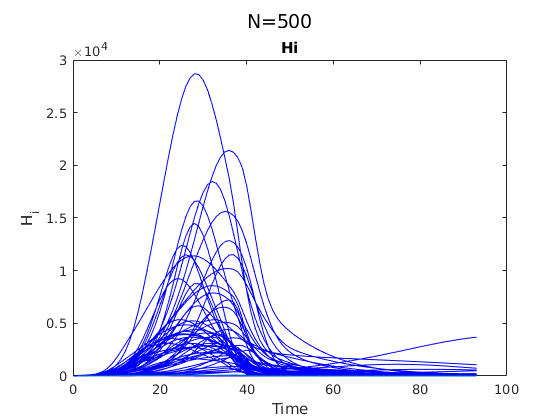

%Comparison with real data
hold on 
plot(xdata,ydata)
ylabel('H_i')
xlabel('Time')

%Selected estimations plot
figure(2)
gsua_eval(FilterPar,T,xdata);

Sim2 Done
Sim1 Done
Sim6 Done
Sim21 Done
Sim5 Done
Sim9 Done
Sim32 Done
Sim4 Done
Sim3 Done
Sim14 Done
Sim13 Done
Sim12 Done
Sim11 Done
Sim10 Done
Sim8 Done
Sim7 Done
Sim45 Done
Sim44 Done
Sim43 Done
Sim42 Done
Sim41 Done
Sim40 Done
Sim20 Done
Sim19 Done
Sim18 Done
Sim17 Done
Sim16 Done
Sim15 Done
Sim58 Done
Sim57 Done
Sim56 Done
Sim55 Done
Sim54 Done
Sim53 Done
Sim52 Done
Sim51 Done
Sim50 Done
Sim84 Done
Sim83 Done
Sim82 Done
Sim81 Done
Sim80 Done
Sim79 Done
Sim78 Done
Sim77 Done
Sim76 Done
Sim75 Done
Sim74 Done
Sim39 Done
Sim38 Done
Sim37 Done
Sim36 Done
Sim35 Done
Sim34 Done
Sim33 Done
Sim71 Done
Sim70 Done
Sim69 Done
Sim68 Done
Sim67 Done
Sim66 Done
Sim65 Done
Sim64 Done
Sim63 Done
Sim62 Done
Sim61 Done
Sim60 Done
Sim73 Done
Sim72 Done
Sim110 Done
Sim109 Done
Sim108 Done
Sim107 Done
Sim59 Done
Sim31 Done
Sim30 Done
Sim29 Done
Sim28 Done
Sim27 Done
Sim26 Done
Sim25 Done
Sim24 Done
Sim23 Done
Sim22 Done
Sim160 Done
Sim159 Done
Sim158 Done
Sim157 Done
Sim156 Done
Sim155 Done
Sim49 Don

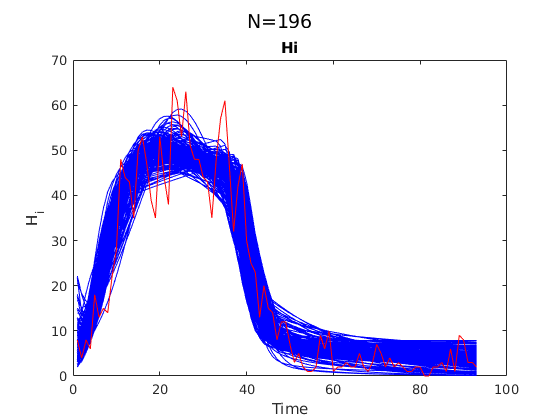

%Comparison with real data
hold on 
plot(xdata,ydata,'r')
ylabel('H_i')
xlabel('Time')

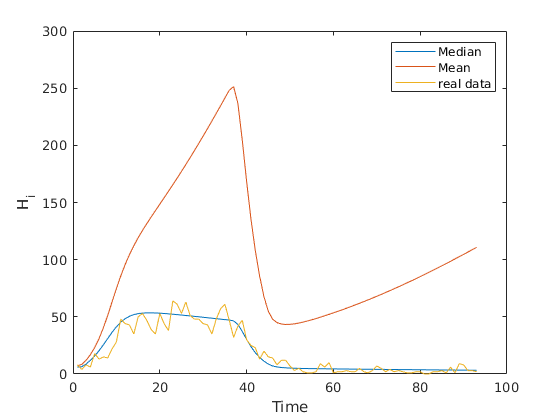

%Centrality statistics of filtered estimations
Median=median(FilterPar')';
Mean=mean(FilterPar')';
%Plot of nominal curves using centrality statistics 
figure(3)
S=gsua_pardeval([Median';Mean'],T,xdata,0);%Evaluation of both nominal curves
plot(S(1,:))
hold on 
plot(S(2,:))
%Comparison with real data
plot(xdata,ydata)
legend('Median','Mean','real data')
ylabel('H_i')
xlabel('Time')

## 4. Confidence interval with median 

As can see in the above section,  the nominal value estimated with the median fit better to the real data. Thus, in this section, we estimate confidence intervals for each nominal parameter of that statistic.

First, we will use the following equation:

$\theta_i = \mbox{median}(\hat{\theta}_i) \pm 1.96 \sqrt{\frac{\pi}{2}}\frac{\sigma_{m_i}}{\sqrt{N_i}}$     (2)

based on the order statistic of the normal distribution. Where $N_i$ is the number of samples and $\sigma_{m_i}$ is the standard deviation of each parameter.

[r, c]=size(FilterPar);%c: Number of filtered estimations, r:number of parameters
standarDesv = std(FilterPar');
%Determine the upper and lower limits of confidence intervals
DistM=1.96*sqrt(pi)*standarDesv/(sqrt(c-1));
intervalinf=Median - DistM';
intervalsup=Median + DistM';
%The intervals are annexed to object T
InterMedia=[intervalinf, intervalsup];
T.Range=InterMedia;
%The median is annexed to object T as nominal value
T.Nominal=Median;

To evaluate the confidence intervals obtained from equation (2), we perform an uncertainty analysis:

Starting parallel pool (parpool) using the 'local' profile ...
Preserving jobs with IDs: 1 2 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile local. To create 'myCluster' use 'myCluster = parcluster('local')'.
connected to 8 workers.
Progress: 100%
Estimated processing time (h:m:s): 0:0:36
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:36
Estimated stop time (h:m:s): 12:13:16
Number of simulations: 1000


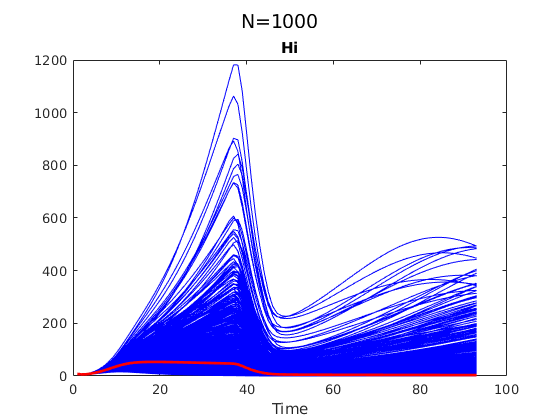

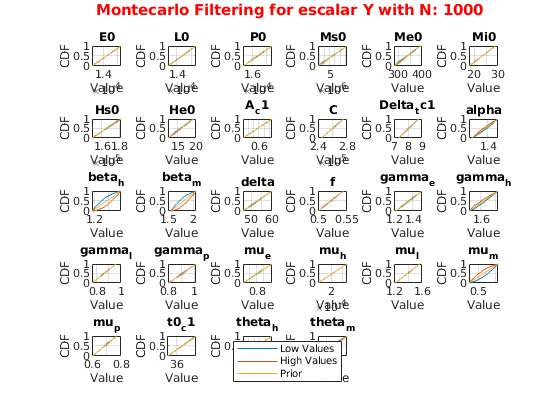

[M,T]=gsua_dmatrix(T,1000,'Show','off');
gsua_ua(M,T,'xdata',xdata);

##  5. Confidence Sub-contour Box (CSB)

As can see from the above section, the intervals obtained from the equation (2) present an inadequate uncertainty analysis due to the number of outlier curves those generate. Thus, in this section, we implemented a method that estimates a kind of confidence intervals known as Confidence Sub-contour Box  (see [this](https://arxiv.org/abs/1909.09603) for more information), this method guarantees at least 95% of the curves generated from the estimated intervals are near to the nominal curve.

Expansion-reduction Method OAT is being launched
------------------------------------
Calculus of theta_m Starting
Range for theta_m Done!
Initial range of theta_m(28)--> 0.4           1
Actual range --> 0.53052     0.66956
Calculus of theta_h Starting
Range for theta_h Done!
Initial range of theta_h(27)--> 0.4         1.8
Actual range --> 0.42335      1.0673
Calculus of t0_c1 Starting
Range for t0_c1 Done!
Initial range of t0_c1(26)--> 32  38
Actual range --> 27.7706      44.2673
Calculus of mu_p Starting
Activating intern_counter for mu_p
Activating intern_counter for mu_p
Range for mu_p Done!
Initial range of mu_p(25)--> 0         1.4
Actual range --> 0       1.546
Calculus of mu_m Starting
Range for mu_m Done!
Initial range of mu_m(24)--> 0         0.9
Actual range --> 0.49924     0.53753
Calculus of mu_l Starting
Range for mu_l Done!
Initial range of mu_l(23)--> 0        3.22
Actual range --> 0.29368      2.6129
Calculus of mu_h Starting
Activating intern_counter for mu_h
Activati

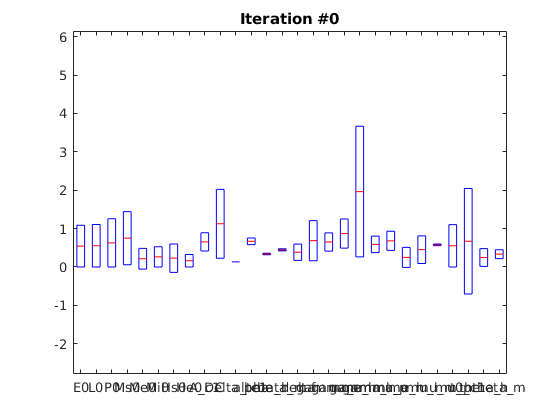

%Define the initial parameter intervals as the estimation ranges for the
%gsua_oatr() function
T.Range=Ranges(3:end,:);
%OAT interval calculation for gsua_ucis() function
RangesOAT=gsua_oatr(T,'parallel',false);

Before run gsa_ucis (to obtain CSB) check the results performed by oat funcion, sometimes this function put 'inf' in upper bound for t_0i parameters; if it occurs, you will change 'inf' for another upper bound.

%Chek OAT results
for i=1: size(RangesOAT,1)
    if RangesOAT.Range(i,2)==inf
        RangesOAT.Range(i,2)=50;
    end
end

We run the gsua_ucis function to estimated the CSB for each parameter, using the OAT ranges obtained before. This function shows the number of iterations until converging, and uncertainty analysis; the last shows the nominal curve, the 'right' curves, and the outliers.

In this case, estimating using the CSB method gives a better uncertainty than the intervals obtained in equation (2).

T2=gsua_ucis(RangesOAT,1000,'reps',1000,'parallel',true)

------------------------------------
Ranges calculation is being launched
------------------------------------
Starting parallel pool (parpool) using the 'local' profile ...
Preserving jobs with IDs: 1 2 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile local. To create 'myCluster' use 'myCluster = parcluster('local')'.
connected to 8 workers.
Progress: 1%
Estimated processing time (h:m:s): 12:6:57
Remaining time (h:m:s): 12:6:13
Elapsed time (h:m:s): 0:0:43
Estimated stop time (h:m:s): 28:26:28
Number of simulations: 1000000


------------------------------------
43 Scalars has been detected in the especified range
------------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 1%
Estimated processing time (h:m:s): 9:11:42
Remaining time (h:m:s): 9:10:36
Elapsed time (h:m:s): 0:1:6
Estimated stop time (h:m:s): 25:31:14
Number of simulations: 1000000


------------------------------------
86 Scalars has been detected in the especified range
------------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 1%
Estimated processing time (h:m:s): 8:10:19
Remaining time (h:m:s): 8:8:51
Elapsed time (h:m:s): 0:1:28
Estimated stop time (h:m:s): 24:29:51
Number of simulations: 1000000


------------------------------------
115 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 1%
Estimated processing time (h:m:s): 7:45:9
Remaining time (h:m:s): 7:43:18
Elapsed time (h:m:s): 0:1:51
Estimated stop time (h:m:s): 24:4:41
Number of simulations: 1000000


------------------------------------
123 Scalars has been detected in the especified range
------------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 1%
Estimated processing time (h:m:s): 7:26:46
Remaining time (h:m:s): 7:24:32
Elapsed time (h:m:s): 0:2:14
Estimated stop time (h:m:s): 23:46:18
Number of simulations: 1000000


------------------------------------
125 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


4--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 1%
Estimated processing time (h:m:s): 7:20:13
Remaining time (h:m:s): 7:17:35
Elapsed time (h:m:s): 0:2:38
Estimated stop time (h:m:s): 23:39:45
Number of simulations: 1000000


------------------------------------
120 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 1%
Estimated processing time (h:m:s): 7:16:4
Remaining time (h:m:s): 7:13:0
Elapsed time (h:m:s): 0:3:3
Estimated stop time (h:m:s): 23:35:35
Number of simulations: 1000000


------------------------------------
121 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 1%
Estimated processing time (h:m:s): 7:16:18
Remaining time (h:m:s): 7:12:48
Elapsed time (h:m:s): 0:3:29
Estimated stop time (h:m:s): 23:35:49
Number of simulations: 1000000


------------------------------------
160 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 1%
Estimated processing time (h:m:s): 7:17:25
Remaining time (h:m:s): 7:13:29
Elapsed time (h:m:s): 0:3:56
Estimated stop time (h:m:s): 23:36:57
Number of simulations: 1000000


------------------------------------
154 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 1%
Estimated processing time (h:m:s): 7:13:20
Remaining time (h:m:s): 7:9:0
Elapsed time (h:m:s): 0:4:20
Estimated stop time (h:m:s): 23:32:51
Number of simulations: 1000000


------------------------------------
130 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 2%
Estimated processing time (h:m:s): 7:10:17
Remaining time (h:m:s): 7:5:33
Elapsed time (h:m:s): 0:4:43
Estimated stop time (h:m:s): 23:29:49
Number of simulations: 1000000


------------------------------------
138 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 2%
Estimated processing time (h:m:s): 7:10:11
Remaining time (h:m:s): 7:5:1
Elapsed time (h:m:s): 0:5:9
Estimated stop time (h:m:s): 23:29:43
Number of simulations: 1000000


------------------------------------
154 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 2%
Estimated processing time (h:m:s): 7:8:12
Remaining time (h:m:s): 7:2:38
Elapsed time (h:m:s): 0:5:33
Estimated stop time (h:m:s): 23:27:43
Number of simulations: 1000000


------------------------------------
183 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 2%
Estimated processing time (h:m:s): 7:6:44
Remaining time (h:m:s): 7:0:46
Elapsed time (h:m:s): 0:5:58
Estimated stop time (h:m:s): 23:26:16
Number of simulations: 1000000


------------------------------------
143 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 2%
Estimated processing time (h:m:s): 7:6:12
Remaining time (h:m:s): 6:59:48
Elapsed time (h:m:s): 0:6:23
Estimated stop time (h:m:s): 23:25:43
Number of simulations: 1000000


------------------------------------
163 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 2%
Estimated processing time (h:m:s): 7:4:37
Remaining time (h:m:s): 6:57:49
Elapsed time (h:m:s): 0:6:47
Estimated stop time (h:m:s): 23:24:8
Number of simulations: 1000000


------------------------------------
173 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 2%
Estimated processing time (h:m:s): 7:2:50
Remaining time (h:m:s): 6:55:38
Elapsed time (h:m:s): 0:7:11
Estimated stop time (h:m:s): 23:22:21
Number of simulations: 1000000


------------------------------------
195 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 2%
Estimated processing time (h:m:s): 7:1:23
Remaining time (h:m:s): 6:53:48
Elapsed time (h:m:s): 0:7:35
Estimated stop time (h:m:s): 23:20:54
Number of simulations: 1000000


------------------------------------
158 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.1422"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


17--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 2%
Estimated processing time (h:m:s): 7:3:25
Remaining time (h:m:s): 6:55:22
Elapsed time (h:m:s): 0:8:2
Estimated stop time (h:m:s): 23:22:57
Number of simulations: 1000000


------------------------------------
310 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 2%
Estimated processing time (h:m:s): 7:2:51
Remaining time (h:m:s): 6:54:24
Elapsed time (h:m:s): 0:8:27
Estimated stop time (h:m:s): 23:22:23
Number of simulations: 1000000


------------------------------------
316 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 3%
Estimated processing time (h:m:s): 7:3:32
Remaining time (h:m:s): 6:54:39
Elapsed time (h:m:s): 0:8:53
Estimated stop time (h:m:s): 23:23:4
Number of simulations: 1000000


------------------------------------
326 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 3%
Estimated processing time (h:m:s): 7:2:35
Remaining time (h:m:s): 6:53:17
Elapsed time (h:m:s): 0:9:17
Estimated stop time (h:m:s): 23:22:7
Number of simulations: 1000000


------------------------------------
313 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 3%
Estimated processing time (h:m:s): 7:2:2
Remaining time (h:m:s): 6:52:20
Elapsed time (h:m:s): 0:9:42
Estimated stop time (h:m:s): 23:21:34
Number of simulations: 1000000


------------------------------------
345 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 3%
Estimated processing time (h:m:s): 7:2:13
Remaining time (h:m:s): 6:52:5
Elapsed time (h:m:s): 0:10:7
Estimated stop time (h:m:s): 23:21:44
Number of simulations: 1000000


------------------------------------
317 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 3%
Estimated processing time (h:m:s): 7:2:23
Remaining time (h:m:s): 6:51:49
Elapsed time (h:m:s): 0:10:33
Estimated stop time (h:m:s): 23:21:54
Number of simulations: 1000000


------------------------------------
321 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 3%
Estimated processing time (h:m:s): 7:1:42
Remaining time (h:m:s): 6:50:44
Elapsed time (h:m:s): 0:10:57
Estimated stop time (h:m:s): 23:21:13
Number of simulations: 1000000


------------------------------------
357 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 3%
Estimated processing time (h:m:s): 7:1:47
Remaining time (h:m:s): 6:50:24
Elapsed time (h:m:s): 0:11:23
Estimated stop time (h:m:s): 23:21:18
Number of simulations: 1000000


------------------------------------
305 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 3%
Estimated processing time (h:m:s): 7:1:35
Remaining time (h:m:s): 6:49:47
Elapsed time (h:m:s): 0:11:48
Estimated stop time (h:m:s): 23:21:7
Number of simulations: 1000000


------------------------------------
341 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 3%
Estimated processing time (h:m:s): 7:0:47
Remaining time (h:m:s): 6:48:35
Elapsed time (h:m:s): 0:12:12
Estimated stop time (h:m:s): 23:20:19
Number of simulations: 1000000


------------------------------------
344 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 3%
Estimated processing time (h:m:s): 7:1:2
Remaining time (h:m:s): 6:48:24
Elapsed time (h:m:s): 0:12:37
Estimated stop time (h:m:s): 23:20:34
Number of simulations: 1000000


------------------------------------
369 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.3321"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


10--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 4%
Estimated processing time (h:m:s): 7:3:13
Remaining time (h:m:s): 6:50:5
Elapsed time (h:m:s): 0:13:7
Estimated stop time (h:m:s): 23:22:44
Number of simulations: 1000000


------------------------------------
338 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 4%
Estimated processing time (h:m:s): 7:2:57
Remaining time (h:m:s): 6:49:25
Elapsed time (h:m:s): 0:13:32
Estimated stop time (h:m:s): 23:22:29
Number of simulations: 1000000


------------------------------------
357 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 4%
Estimated processing time (h:m:s): 7:2:26
Remaining time (h:m:s): 6:48:30
Elapsed time (h:m:s): 0:13:56
Estimated stop time (h:m:s): 23:21:58
Number of simulations: 1000000


------------------------------------
369 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 4%
Estimated processing time (h:m:s): 7:2:11
Remaining time (h:m:s): 6:47:49
Elapsed time (h:m:s): 0:14:21
Estimated stop time (h:m:s): 23:21:42
Number of simulations: 1000000


------------------------------------
345 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 4%
Estimated processing time (h:m:s): 7:1:57
Remaining time (h:m:s): 6:47:11
Elapsed time (h:m:s): 0:14:46
Estimated stop time (h:m:s): 23:21:28
Number of simulations: 1000000


------------------------------------
346 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 4%
Estimated processing time (h:m:s): 7:1:35
Remaining time (h:m:s): 6:46:25
Elapsed time (h:m:s): 0:15:10
Estimated stop time (h:m:s): 23:21:7
Number of simulations: 1000000


------------------------------------
352 Scalars has been detected in the especified range
------------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 4%
Estimated processing time (h:m:s): 7:0:42
Remaining time (h:m:s): 6:45:8
Elapsed time (h:m:s): 0:15:33
Estimated stop time (h:m:s): 23:20:14
Number of simulations: 1000000


------------------------------------
358 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 4%
Estimated processing time (h:m:s): 7:1:5
Remaining time (h:m:s): 6:45:5
Elapsed time (h:m:s): 0:16:0
Estimated stop time (h:m:s): 23:20:37
Number of simulations: 1000000


------------------------------------
388 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 4%
Estimated processing time (h:m:s): 7:1:15
Remaining time (h:m:s): 6:44:49
Elapsed time (h:m:s): 0:16:25
Estimated stop time (h:m:s): 23:20:47
Number of simulations: 1000000


------------------------------------
350 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 4%
Estimated processing time (h:m:s): 7:0:55
Remaining time (h:m:s): 6:44:5
Elapsed time (h:m:s): 0:16:50
Estimated stop time (h:m:s): 23:20:26
Number of simulations: 1000000


------------------------------------
353 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 5%
Estimated processing time (h:m:s): 7:0:48
Remaining time (h:m:s): 6:43:33
Elapsed time (h:m:s): 0:17:15
Estimated stop time (h:m:s): 23:20:20
Number of simulations: 1000000


------------------------------------
360 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 5%
Estimated processing time (h:m:s): 7:0:38
Remaining time (h:m:s): 6:42:58
Elapsed time (h:m:s): 0:17:40
Estimated stop time (h:m:s): 23:20:9
Number of simulations: 1000000


------------------------------------
367 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.3303"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


5--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 5%
Estimated processing time (h:m:s): 7:2:17
Remaining time (h:m:s): 6:44:7
Elapsed time (h:m:s): 0:18:9
Estimated stop time (h:m:s): 23:21:49
Number of simulations: 1000000


------------------------------------
387 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 5%
Estimated processing time (h:m:s): 7:2:12
Remaining time (h:m:s): 6:43:38
Elapsed time (h:m:s): 0:18:34
Estimated stop time (h:m:s): 23:21:44
Number of simulations: 1000000


------------------------------------
399 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 5%
Estimated processing time (h:m:s): 7:2:41
Remaining time (h:m:s): 6:43:39
Elapsed time (h:m:s): 0:19:1
Estimated stop time (h:m:s): 23:22:12
Number of simulations: 1000000


------------------------------------
372 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 5%
Estimated processing time (h:m:s): 7:2:42
Remaining time (h:m:s): 6:43:15
Elapsed time (h:m:s): 0:19:26
Estimated stop time (h:m:s): 23:22:14
Number of simulations: 1000000


------------------------------------
413 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 5%
Estimated processing time (h:m:s): 7:3:18
Remaining time (h:m:s): 6:43:24
Elapsed time (h:m:s): 0:19:53
Estimated stop time (h:m:s): 23:22:49
Number of simulations: 1000000


------------------------------------
397 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 5%
Estimated processing time (h:m:s): 7:3:3
Remaining time (h:m:s): 6:42:45
Elapsed time (h:m:s): 0:20:18
Estimated stop time (h:m:s): 23:22:35
Number of simulations: 1000000


------------------------------------
392 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 5%
Estimated processing time (h:m:s): 7:2:55
Remaining time (h:m:s): 6:42:12
Elapsed time (h:m:s): 0:20:43
Estimated stop time (h:m:s): 23:22:27
Number of simulations: 1000000


------------------------------------
386 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 5%
Estimated processing time (h:m:s): 7:2:55
Remaining time (h:m:s): 6:41:47
Elapsed time (h:m:s): 0:21:8
Estimated stop time (h:m:s): 23:22:27
Number of simulations: 1000000


------------------------------------
395 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 6%
Estimated processing time (h:m:s): 7:2:54
Remaining time (h:m:s): 6:41:20
Elapsed time (h:m:s): 0:21:34
Estimated stop time (h:m:s): 23:22:26
Number of simulations: 1000000


------------------------------------
408 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 6%
Estimated processing time (h:m:s): 7:2:59
Remaining time (h:m:s): 6:40:59
Elapsed time (h:m:s): 0:21:59
Estimated stop time (h:m:s): 23:22:31
Number of simulations: 1000000


------------------------------------
390 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 6%
Estimated processing time (h:m:s): 7:2:48
Remaining time (h:m:s): 6:40:23
Elapsed time (h:m:s): 0:22:24
Estimated stop time (h:m:s): 23:22:19
Number of simulations: 1000000


------------------------------------
389 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 6%
Estimated processing time (h:m:s): 7:2:51
Remaining time (h:m:s): 6:40:1
Elapsed time (h:m:s): 0:22:50
Estimated stop time (h:m:s): 23:22:22
Number of simulations: 1000000


------------------------------------
382 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 6%
Estimated processing time (h:m:s): 7:2:40
Remaining time (h:m:s): 6:39:26
Elapsed time (h:m:s): 0:23:14
Estimated stop time (h:m:s): 23:22:12
Number of simulations: 1000000


------------------------------------
377 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 6%
Estimated processing time (h:m:s): 7:2:55
Remaining time (h:m:s): 6:39:14
Elapsed time (h:m:s): 0:23:41
Estimated stop time (h:m:s): 23:22:27
Number of simulations: 1000000


------------------------------------
403 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 6%
Estimated processing time (h:m:s): 7:2:46
Remaining time (h:m:s): 6:38:40
Elapsed time (h:m:s): 0:24:5
Estimated stop time (h:m:s): 23:22:18
Number of simulations: 1000000


------------------------------------
403 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 6%
Estimated processing time (h:m:s): 7:2:28
Remaining time (h:m:s): 6:37:57
Elapsed time (h:m:s): 0:24:30
Estimated stop time (h:m:s): 23:21:59
Number of simulations: 1000000


------------------------------------
431 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 6%
Estimated processing time (h:m:s): 7:2:12
Remaining time (h:m:s): 6:37:17
Elapsed time (h:m:s): 0:24:54
Estimated stop time (h:m:s): 23:21:43
Number of simulations: 1000000


------------------------------------
403 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 6%
Estimated processing time (h:m:s): 7:2:17
Remaining time (h:m:s): 6:36:57
Elapsed time (h:m:s): 0:25:20
Estimated stop time (h:m:s): 23:21:49
Number of simulations: 1000000


------------------------------------
415 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 7%
Estimated processing time (h:m:s): 7:2:4
Remaining time (h:m:s): 6:36:20
Elapsed time (h:m:s): 0:25:44
Estimated stop time (h:m:s): 23:21:36
Number of simulations: 1000000


------------------------------------
411 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 7%
Estimated processing time (h:m:s): 7:2:1
Remaining time (h:m:s): 6:35:51
Elapsed time (h:m:s): 0:26:9
Estimated stop time (h:m:s): 23:21:33
Number of simulations: 1000000


------------------------------------
406 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 7%
Estimated processing time (h:m:s): 7:1:59
Remaining time (h:m:s): 6:35:24
Elapsed time (h:m:s): 0:26:35
Estimated stop time (h:m:s): 23:21:31
Number of simulations: 1000000


------------------------------------
404 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 7%
Estimated processing time (h:m:s): 7:1:57
Remaining time (h:m:s): 6:34:57
Elapsed time (h:m:s): 0:27:0
Estimated stop time (h:m:s): 23:21:29
Number of simulations: 1000000


------------------------------------
431 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 7%
Estimated processing time (h:m:s): 7:2:11
Remaining time (h:m:s): 6:34:45
Elapsed time (h:m:s): 0:27:26
Estimated stop time (h:m:s): 23:21:43
Number of simulations: 1000000


------------------------------------
439 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 7%
Estimated processing time (h:m:s): 7:2:24
Remaining time (h:m:s): 6:34:32
Elapsed time (h:m:s): 0:27:52
Estimated stop time (h:m:s): 23:21:56
Number of simulations: 1000000


------------------------------------
427 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 7%
Estimated processing time (h:m:s): 7:2:11
Remaining time (h:m:s): 6:33:53
Elapsed time (h:m:s): 0:28:17
Estimated stop time (h:m:s): 23:21:42
Number of simulations: 1000000


------------------------------------
399 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 7%
Estimated processing time (h:m:s): 7:1:58
Remaining time (h:m:s): 6:33:17
Elapsed time (h:m:s): 0:28:41
Estimated stop time (h:m:s): 23:21:30
Number of simulations: 1000000


------------------------------------
406 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 7%
Estimated processing time (h:m:s): 7:1:48
Remaining time (h:m:s): 6:32:42
Elapsed time (h:m:s): 0:29:6
Estimated stop time (h:m:s): 23:21:20
Number of simulations: 1000000


------------------------------------
444 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.3996"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 7%
Estimated processing time (h:m:s): 7:2:42
Remaining time (h:m:s): 6:33:7
Elapsed time (h:m:s): 0:29:35
Estimated stop time (h:m:s): 23:22:14
Number of simulations: 1000000


------------------------------------
451 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.4059"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 8%
Estimated processing time (h:m:s): 7:3:35
Remaining time (h:m:s): 6:33:30
Elapsed time (h:m:s): 0:30:4
Estimated stop time (h:m:s): 23:23:6
Number of simulations: 1000000


------------------------------------
454 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 8%
Estimated processing time (h:m:s): 7:3:23
Remaining time (h:m:s): 6:32:54
Elapsed time (h:m:s): 0:30:29
Estimated stop time (h:m:s): 23:22:55
Number of simulations: 1000000


------------------------------------
450 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 8%
Estimated processing time (h:m:s): 7:3:8
Remaining time (h:m:s): 6:32:15
Elapsed time (h:m:s): 0:30:53
Estimated stop time (h:m:s): 23:22:40
Number of simulations: 1000000


------------------------------------
444 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 8%
Estimated processing time (h:m:s): 7:2:55
Remaining time (h:m:s): 6:31:37
Elapsed time (h:m:s): 0:31:17
Estimated stop time (h:m:s): 23:22:26
Number of simulations: 1000000


------------------------------------
447 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 8%
Estimated processing time (h:m:s): 7:2:41
Remaining time (h:m:s): 6:30:59
Elapsed time (h:m:s): 0:31:42
Estimated stop time (h:m:s): 23:22:13
Number of simulations: 1000000


------------------------------------
451 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 8%
Estimated processing time (h:m:s): 7:2:27
Remaining time (h:m:s): 6:30:21
Elapsed time (h:m:s): 0:32:6
Estimated stop time (h:m:s): 23:21:59
Number of simulations: 1000000


------------------------------------
432 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 8%
Estimated processing time (h:m:s): 7:2:12
Remaining time (h:m:s): 6:29:42
Elapsed time (h:m:s): 0:32:30
Estimated stop time (h:m:s): 23:21:44
Number of simulations: 1000000


------------------------------------
463 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.4167"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 8%
Estimated processing time (h:m:s): 7:3:8
Remaining time (h:m:s): 6:30:8
Elapsed time (h:m:s): 0:33:0
Estimated stop time (h:m:s): 23:22:40
Number of simulations: 1000000


------------------------------------
463 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 8%
Estimated processing time (h:m:s): 7:3:21
Remaining time (h:m:s): 6:29:54
Elapsed time (h:m:s): 0:33:26
Estimated stop time (h:m:s): 23:22:52
Number of simulations: 1000000


------------------------------------
482 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 8%
Estimated processing time (h:m:s): 7:3:30
Remaining time (h:m:s): 6:29:37
Elapsed time (h:m:s): 0:33:52
Estimated stop time (h:m:s): 23:23:2
Number of simulations: 1000000


------------------------------------
429 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 9%
Estimated processing time (h:m:s): 7:3:24
Remaining time (h:m:s): 6:29:6
Elapsed time (h:m:s): 0:34:17
Estimated stop time (h:m:s): 23:22:56
Number of simulations: 1000000


------------------------------------
463 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 9%
Estimated processing time (h:m:s): 7:3:15
Remaining time (h:m:s): 6:28:32
Elapsed time (h:m:s): 0:34:42
Estimated stop time (h:m:s): 23:22:46
Number of simulations: 1000000


------------------------------------
494 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


4--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 9%
Estimated processing time (h:m:s): 7:3:5
Remaining time (h:m:s): 6:27:58
Elapsed time (h:m:s): 0:35:7
Estimated stop time (h:m:s): 23:22:37
Number of simulations: 1000000


------------------------------------
477 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 9%
Estimated processing time (h:m:s): 7:3:21
Remaining time (h:m:s): 6:27:48
Elapsed time (h:m:s): 0:35:33
Estimated stop time (h:m:s): 23:22:53
Number of simulations: 1000000


------------------------------------
452 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 9%
Estimated processing time (h:m:s): 7:3:14
Remaining time (h:m:s): 6:27:16
Elapsed time (h:m:s): 0:35:58
Estimated stop time (h:m:s): 23:22:46
Number of simulations: 1000000


------------------------------------
449 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 9%
Estimated processing time (h:m:s): 7:3:9
Remaining time (h:m:s): 6:26:45
Elapsed time (h:m:s): 0:36:23
Estimated stop time (h:m:s): 23:22:40
Number of simulations: 1000000


------------------------------------
505 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


4--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 9%
Estimated processing time (h:m:s): 7:3:4
Remaining time (h:m:s): 6:26:15
Elapsed time (h:m:s): 0:36:48
Estimated stop time (h:m:s): 23:22:35
Number of simulations: 1000000


------------------------------------
475 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 9%
Estimated processing time (h:m:s): 7:2:58
Remaining time (h:m:s): 6:25:44
Elapsed time (h:m:s): 0:37:13
Estimated stop time (h:m:s): 23:22:29
Number of simulations: 1000000


------------------------------------
468 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 9%
Estimated processing time (h:m:s): 7:3:0
Remaining time (h:m:s): 6:25:21
Elapsed time (h:m:s): 0:37:38
Estimated stop time (h:m:s): 23:22:31
Number of simulations: 1000000


------------------------------------
496 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 9%
Estimated processing time (h:m:s): 7:2:56
Remaining time (h:m:s): 6:24:52
Elapsed time (h:m:s): 0:38:3
Estimated stop time (h:m:s): 23:22:27
Number of simulations: 1000000


------------------------------------
513 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 10%
Estimated processing time (h:m:s): 7:2:50
Remaining time (h:m:s): 6:24:21
Elapsed time (h:m:s): 0:38:28
Estimated stop time (h:m:s): 23:22:21
Number of simulations: 1000000


------------------------------------
462 Scalars has been detected in the especified range
------------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 10%
Estimated processing time (h:m:s): 7:2:29
Remaining time (h:m:s): 6:23:37
Elapsed time (h:m:s): 0:38:52
Estimated stop time (h:m:s): 23:22:1
Number of simulations: 1000000


------------------------------------
484 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 10%
Estimated processing time (h:m:s): 7:2:40
Remaining time (h:m:s): 6:23:22
Elapsed time (h:m:s): 0:39:18
Estimated stop time (h:m:s): 23:22:12
Number of simulations: 1000000


------------------------------------
498 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 10%
Estimated processing time (h:m:s): 7:2:51
Remaining time (h:m:s): 6:23:6
Elapsed time (h:m:s): 0:39:44
Estimated stop time (h:m:s): 23:22:23
Number of simulations: 1000000


------------------------------------
496 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 10%
Estimated processing time (h:m:s): 7:2:42
Remaining time (h:m:s): 6:22:33
Elapsed time (h:m:s): 0:40:9
Estimated stop time (h:m:s): 23:22:14
Number of simulations: 1000000


------------------------------------
504 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.4536"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.40824"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


4--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 10%
Estimated processing time (h:m:s): 7:4:23
Remaining time (h:m:s): 6:23:38
Elapsed time (h:m:s): 0:40:44
Estimated stop time (h:m:s): 23:23:54
Number of simulations: 1000000


------------------------------------
520 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.468"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.4212"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.37908"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 10%
Estimated processing time (h:m:s): 7:6:48
Remaining time (h:m:s): 6:25:24
Elapsed time (h:m:s): 0:41:24
Estimated stop time (h:m:s): 23:26:20
Number of simulations: 1000000


------------------------------------
515 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 10%
Estimated processing time (h:m:s): 7:6:36
Remaining time (h:m:s): 6:24:47
Elapsed time (h:m:s): 0:41:48
Estimated stop time (h:m:s): 23:26:7
Number of simulations: 1000000


------------------------------------
503 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 10%
Estimated processing time (h:m:s): 7:6:27
Remaining time (h:m:s): 6:24:14
Elapsed time (h:m:s): 0:42:13
Estimated stop time (h:m:s): 23:25:59
Number of simulations: 1000000


------------------------------------
518 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 10%
Estimated processing time (h:m:s): 7:6:32
Remaining time (h:m:s): 6:23:53
Elapsed time (h:m:s): 0:42:39
Estimated stop time (h:m:s): 23:26:3
Number of simulations: 1000000


------------------------------------
520 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 11%
Estimated processing time (h:m:s): 7:6:40
Remaining time (h:m:s): 6:23:35
Elapsed time (h:m:s): 0:43:5
Estimated stop time (h:m:s): 23:26:12
Number of simulations: 1000000


------------------------------------
546 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 11%
Estimated processing time (h:m:s): 7:6:33
Remaining time (h:m:s): 6:23:2
Elapsed time (h:m:s): 0:43:30
Estimated stop time (h:m:s): 23:26:5
Number of simulations: 1000000


------------------------------------
522 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 11%
Estimated processing time (h:m:s): 7:6:19
Remaining time (h:m:s): 6:22:24
Elapsed time (h:m:s): 0:43:54
Estimated stop time (h:m:s): 23:25:51
Number of simulations: 1000000


------------------------------------
547 Scalars has been detected in the especified range
------------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 11%
Estimated processing time (h:m:s): 7:5:53
Remaining time (h:m:s): 6:21:36
Elapsed time (h:m:s): 0:44:17
Estimated stop time (h:m:s): 23:25:25
Number of simulations: 1000000


------------------------------------
546 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 11%
Estimated processing time (h:m:s): 7:5:46
Remaining time (h:m:s): 6:21:4
Elapsed time (h:m:s): 0:44:42
Estimated stop time (h:m:s): 23:25:18
Number of simulations: 1000000


------------------------------------
547 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 11%
Estimated processing time (h:m:s): 7:5:34
Remaining time (h:m:s): 6:20:27
Elapsed time (h:m:s): 0:45:6
Estimated stop time (h:m:s): 23:25:5
Number of simulations: 1000000


------------------------------------
541 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 11%
Estimated processing time (h:m:s): 7:5:25
Remaining time (h:m:s): 6:19:53
Elapsed time (h:m:s): 0:45:31
Estimated stop time (h:m:s): 23:24:56
Number of simulations: 1000000


------------------------------------
521 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


4--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 11%
Estimated processing time (h:m:s): 7:5:12
Remaining time (h:m:s): 6:19:17
Elapsed time (h:m:s): 0:45:55
Estimated stop time (h:m:s): 23:24:44
Number of simulations: 1000000


------------------------------------
544 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 11%
Estimated processing time (h:m:s): 7:5:0
Remaining time (h:m:s): 6:18:40
Elapsed time (h:m:s): 0:46:19
Estimated stop time (h:m:s): 23:24:31
Number of simulations: 1000000


------------------------------------
520 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 11%
Estimated processing time (h:m:s): 7:4:47
Remaining time (h:m:s): 6:18:3
Elapsed time (h:m:s): 0:46:43
Estimated stop time (h:m:s): 23:24:19
Number of simulations: 1000000


------------------------------------
516 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 12%
Estimated processing time (h:m:s): 7:4:35
Remaining time (h:m:s): 6:17:27
Elapsed time (h:m:s): 0:47:7
Estimated stop time (h:m:s): 23:24:7
Number of simulations: 1000000


------------------------------------
540 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 12%
Estimated processing time (h:m:s): 7:4:36
Remaining time (h:m:s): 6:17:3
Elapsed time (h:m:s): 0:47:33
Estimated stop time (h:m:s): 23:24:8
Number of simulations: 1000000


------------------------------------
519 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 12%
Estimated processing time (h:m:s): 7:4:37
Remaining time (h:m:s): 6:16:38
Elapsed time (h:m:s): 0:47:58
Estimated stop time (h:m:s): 23:24:9
Number of simulations: 1000000


------------------------------------
521 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 12%
Estimated processing time (h:m:s): 7:4:41
Remaining time (h:m:s): 6:16:16
Elapsed time (h:m:s): 0:48:24
Estimated stop time (h:m:s): 23:24:13
Number of simulations: 1000000


------------------------------------
554 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 12%
Estimated processing time (h:m:s): 7:4:48
Remaining time (h:m:s): 6:15:56
Elapsed time (h:m:s): 0:48:51
Estimated stop time (h:m:s): 23:24:19
Number of simulations: 1000000


------------------------------------
550 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 12%
Estimated processing time (h:m:s): 7:4:50
Remaining time (h:m:s): 6:15:33
Elapsed time (h:m:s): 0:49:16
Estimated stop time (h:m:s): 23:24:21
Number of simulations: 1000000


------------------------------------
558 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 12%
Estimated processing time (h:m:s): 7:4:34
Remaining time (h:m:s): 6:14:54
Elapsed time (h:m:s): 0:49:40
Estimated stop time (h:m:s): 23:24:6
Number of simulations: 1000000


------------------------------------
555 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 12%
Estimated processing time (h:m:s): 7:4:20
Remaining time (h:m:s): 6:14:16
Elapsed time (h:m:s): 0:50:4
Estimated stop time (h:m:s): 23:23:52
Number of simulations: 1000000


------------------------------------
532 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 12%
Estimated processing time (h:m:s): 7:4:7
Remaining time (h:m:s): 6:13:38
Elapsed time (h:m:s): 0:50:28
Estimated stop time (h:m:s): 23:23:38
Number of simulations: 1000000


------------------------------------
536 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.4824"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 12%
Estimated processing time (h:m:s): 7:4:58
Remaining time (h:m:s): 6:13:58
Elapsed time (h:m:s): 0:50:59
Estimated stop time (h:m:s): 23:24:30
Number of simulations: 1000000


------------------------------------
557 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 13%
Estimated processing time (h:m:s): 7:4:46
Remaining time (h:m:s): 6:13:22
Elapsed time (h:m:s): 0:51:23
Estimated stop time (h:m:s): 23:24:18
Number of simulations: 1000000


------------------------------------
533 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 13%
Estimated processing time (h:m:s): 7:4:32
Remaining time (h:m:s): 6:12:45
Elapsed time (h:m:s): 0:51:47
Estimated stop time (h:m:s): 23:24:4
Number of simulations: 1000000


------------------------------------
543 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 13%
Estimated processing time (h:m:s): 7:4:25
Remaining time (h:m:s): 6:12:13
Elapsed time (h:m:s): 0:52:12
Estimated stop time (h:m:s): 23:23:57
Number of simulations: 1000000


------------------------------------
576 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 13%
Estimated processing time (h:m:s): 7:4:17
Remaining time (h:m:s): 6:11:41
Elapsed time (h:m:s): 0:52:36
Estimated stop time (h:m:s): 23:23:49
Number of simulations: 1000000


------------------------------------
568 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 13%
Estimated processing time (h:m:s): 7:4:27
Remaining time (h:m:s): 6:11:23
Elapsed time (h:m:s): 0:53:3
Estimated stop time (h:m:s): 23:23:58
Number of simulations: 1000000


------------------------------------
563 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 13%
Estimated processing time (h:m:s): 7:4:19
Remaining time (h:m:s): 6:10:51
Elapsed time (h:m:s): 0:53:27
Estimated stop time (h:m:s): 23:23:51
Number of simulations: 1000000


------------------------------------
555 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 13%
Estimated processing time (h:m:s): 7:4:26
Remaining time (h:m:s): 6:10:32
Elapsed time (h:m:s): 0:53:54
Estimated stop time (h:m:s): 23:23:58
Number of simulations: 1000000


------------------------------------
547 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


5--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 13%
Estimated processing time (h:m:s): 7:4:38
Remaining time (h:m:s): 6:10:17
Elapsed time (h:m:s): 0:54:21
Estimated stop time (h:m:s): 23:24:9
Number of simulations: 1000000


------------------------------------
582 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 13%
Estimated processing time (h:m:s): 7:4:30
Remaining time (h:m:s): 6:9:44
Elapsed time (h:m:s): 0:54:45
Estimated stop time (h:m:s): 23:24:1
Number of simulations: 1000000


------------------------------------
600 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 13%
Estimated processing time (h:m:s): 7:4:40
Remaining time (h:m:s): 6:9:27
Elapsed time (h:m:s): 0:55:12
Estimated stop time (h:m:s): 23:24:12
Number of simulations: 1000000


------------------------------------
617 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.5553"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 14%
Estimated processing time (h:m:s): 7:5:33
Remaining time (h:m:s): 6:9:48
Elapsed time (h:m:s): 0:55:44
Estimated stop time (h:m:s): 23:25:5
Number of simulations: 1000000


------------------------------------
611 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 14%
Estimated processing time (h:m:s): 7:5:41
Remaining time (h:m:s): 6:9:30
Elapsed time (h:m:s): 0:56:11
Estimated stop time (h:m:s): 23:25:13
Number of simulations: 1000000


------------------------------------
600 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 14%
Estimated processing time (h:m:s): 7:5:47
Remaining time (h:m:s): 6:9:9
Elapsed time (h:m:s): 0:56:37
Estimated stop time (h:m:s): 23:25:19
Number of simulations: 1000000


------------------------------------
608 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.5472"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.49248"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.44323"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 14%
Estimated processing time (h:m:s): 7:7:53
Remaining time (h:m:s): 6:10:33
Elapsed time (h:m:s): 0:57:20
Estimated stop time (h:m:s): 23:27:24
Number of simulations: 1000000


------------------------------------
620 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.558"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.5022"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.45198"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 14%
Estimated processing time (h:m:s): 7:10:0
Remaining time (h:m:s): 6:11:57
Elapsed time (h:m:s): 0:58:3
Estimated stop time (h:m:s): 23:29:32
Number of simulations: 1000000


------------------------------------
609 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.5481"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.49329"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 14%
Estimated processing time (h:m:s): 7:11:28
Remaining time (h:m:s): 6:12:47
Elapsed time (h:m:s): 0:58:40
Estimated stop time (h:m:s): 23:30:59
Number of simulations: 1000000


------------------------------------
611 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 14%
Estimated processing time (h:m:s): 7:11:37
Remaining time (h:m:s): 6:12:29
Elapsed time (h:m:s): 0:59:7
Estimated stop time (h:m:s): 23:31:9
Number of simulations: 1000000


------------------------------------
590 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 14%
Estimated processing time (h:m:s): 7:11:31
Remaining time (h:m:s): 6:11:58
Elapsed time (h:m:s): 0:59:33
Estimated stop time (h:m:s): 23:31:3
Number of simulations: 1000000


------------------------------------
603 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 14%
Estimated processing time (h:m:s): 7:11:41
Remaining time (h:m:s): 6:11:41
Elapsed time (h:m:s): 1:0:0
Estimated stop time (h:m:s): 23:31:13
Number of simulations: 1000000


------------------------------------
623 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 14%
Estimated processing time (h:m:s): 7:11:34
Remaining time (h:m:s): 6:11:9
Elapsed time (h:m:s): 1:0:25
Estimated stop time (h:m:s): 23:31:6
Number of simulations: 1000000


------------------------------------
657 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 15%
Estimated processing time (h:m:s): 7:11:31
Remaining time (h:m:s): 6:10:40
Elapsed time (h:m:s): 1:0:50
Estimated stop time (h:m:s): 23:31:2
Number of simulations: 1000000


------------------------------------
622 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 15%
Estimated processing time (h:m:s): 7:11:41
Remaining time (h:m:s): 6:10:23
Elapsed time (h:m:s): 1:1:18
Estimated stop time (h:m:s): 23:31:13
Number of simulations: 1000000


------------------------------------
634 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 15%
Estimated processing time (h:m:s): 7:11:49
Remaining time (h:m:s): 6:10:4
Elapsed time (h:m:s): 1:1:45
Estimated stop time (h:m:s): 23:31:21
Number of simulations: 1000000


------------------------------------
615 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


5--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 15%
Estimated processing time (h:m:s): 7:11:53
Remaining time (h:m:s): 6:9:42
Elapsed time (h:m:s): 1:2:11
Estimated stop time (h:m:s): 23:31:25
Number of simulations: 1000000


------------------------------------
638 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 15%
Estimated processing time (h:m:s): 7:11:45
Remaining time (h:m:s): 6:9:9
Elapsed time (h:m:s): 1:2:36
Estimated stop time (h:m:s): 23:31:17
Number of simulations: 1000000


------------------------------------
612 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 15%
Estimated processing time (h:m:s): 7:11:53
Remaining time (h:m:s): 6:8:49
Elapsed time (h:m:s): 1:3:3
Estimated stop time (h:m:s): 23:31:24
Number of simulations: 1000000


------------------------------------
660 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 15%
Estimated processing time (h:m:s): 7:11:44
Remaining time (h:m:s): 6:8:16
Elapsed time (h:m:s): 1:3:28
Estimated stop time (h:m:s): 23:31:16
Number of simulations: 1000000


------------------------------------
625 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 15%
Estimated processing time (h:m:s): 7:11:36
Remaining time (h:m:s): 6:7:43
Elapsed time (h:m:s): 1:3:52
Estimated stop time (h:m:s): 23:31:7
Number of simulations: 1000000


------------------------------------
647 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 15%
Estimated processing time (h:m:s): 7:11:31
Remaining time (h:m:s): 6:7:14
Elapsed time (h:m:s): 1:4:17
Estimated stop time (h:m:s): 23:31:3
Number of simulations: 1000000


------------------------------------
661 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 15%
Estimated processing time (h:m:s): 7:11:22
Remaining time (h:m:s): 6:6:40
Elapsed time (h:m:s): 1:4:42
Estimated stop time (h:m:s): 23:30:54
Number of simulations: 1000000


------------------------------------
624 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 16%
Estimated processing time (h:m:s): 7:11:27
Remaining time (h:m:s): 6:6:18
Elapsed time (h:m:s): 1:5:9
Estimated stop time (h:m:s): 23:30:59
Number of simulations: 1000000


------------------------------------
644 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 16%
Estimated processing time (h:m:s): 7:11:17
Remaining time (h:m:s): 6:5:43
Elapsed time (h:m:s): 1:5:33
Estimated stop time (h:m:s): 23:30:48
Number of simulations: 1000000


------------------------------------
651 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 16%
Estimated processing time (h:m:s): 7:11:20
Remaining time (h:m:s): 6:5:20
Elapsed time (h:m:s): 1:5:59
Estimated stop time (h:m:s): 23:30:52
Number of simulations: 1000000


------------------------------------
611 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 16%
Estimated processing time (h:m:s): 7:11:10
Remaining time (h:m:s): 6:4:46
Elapsed time (h:m:s): 1:6:24
Estimated stop time (h:m:s): 23:30:42
Number of simulations: 1000000


------------------------------------
628 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 16%
Estimated processing time (h:m:s): 7:10:59
Remaining time (h:m:s): 6:4:11
Elapsed time (h:m:s): 1:6:48
Estimated stop time (h:m:s): 23:30:30
Number of simulations: 1000000


------------------------------------
630 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 16%
Estimated processing time (h:m:s): 7:10:48
Remaining time (h:m:s): 6:3:35
Elapsed time (h:m:s): 1:7:12
Estimated stop time (h:m:s): 23:30:19
Number of simulations: 1000000


------------------------------------
663 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.5967"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.53703"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 16%
Estimated processing time (h:m:s): 7:12:16
Remaining time (h:m:s): 6:4:24
Elapsed time (h:m:s): 1:7:52
Estimated stop time (h:m:s): 23:31:48
Number of simulations: 1000000


------------------------------------
640 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 16%
Estimated processing time (h:m:s): 7:12:5
Remaining time (h:m:s): 6:3:49
Elapsed time (h:m:s): 1:8:16
Estimated stop time (h:m:s): 23:31:37
Number of simulations: 1000000


------------------------------------
643 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 16%
Estimated processing time (h:m:s): 7:11:58
Remaining time (h:m:s): 6:3:17
Elapsed time (h:m:s): 1:8:40
Estimated stop time (h:m:s): 23:31:29
Number of simulations: 1000000


------------------------------------
687 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 16%
Estimated processing time (h:m:s): 7:12:1
Remaining time (h:m:s): 6:2:53
Elapsed time (h:m:s): 1:9:7
Estimated stop time (h:m:s): 23:31:32
Number of simulations: 1000000


------------------------------------
674 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 17%
Estimated processing time (h:m:s): 7:11:52
Remaining time (h:m:s): 6:2:20
Elapsed time (h:m:s): 1:9:31
Estimated stop time (h:m:s): 23:31:24
Number of simulations: 1000000


------------------------------------
684 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 17%
Estimated processing time (h:m:s): 7:11:56
Remaining time (h:m:s): 6:1:58
Elapsed time (h:m:s): 1:9:58
Estimated stop time (h:m:s): 23:31:28
Number of simulations: 1000000


------------------------------------
670 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 17%
Estimated processing time (h:m:s): 7:11:59
Remaining time (h:m:s): 6:1:34
Elapsed time (h:m:s): 1:10:24
Estimated stop time (h:m:s): 23:31:31
Number of simulations: 1000000


------------------------------------
667 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6003"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.54027"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.48624"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 17%
Estimated processing time (h:m:s): 7:13:54
Remaining time (h:m:s): 6:2:44
Elapsed time (h:m:s): 1:11:9
Estimated stop time (h:m:s): 23:33:26
Number of simulations: 1000000


------------------------------------
670 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 17%
Estimated processing time (h:m:s): 7:13:47
Remaining time (h:m:s): 6:2:13
Elapsed time (h:m:s): 1:11:34
Estimated stop time (h:m:s): 23:33:19
Number of simulations: 1000000


------------------------------------
661 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 17%
Estimated processing time (h:m:s): 7:13:34
Remaining time (h:m:s): 6:1:36
Elapsed time (h:m:s): 1:11:58
Estimated stop time (h:m:s): 23:33:6
Number of simulations: 1000000


------------------------------------
667 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6003"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.54027"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.48624"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 17%
Estimated processing time (h:m:s): 7:15:27
Remaining time (h:m:s): 6:2:44
Elapsed time (h:m:s): 1:12:43
Estimated stop time (h:m:s): 23:34:59
Number of simulations: 1000000


------------------------------------
667 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 17%
Estimated processing time (h:m:s): 7:15:13
Remaining time (h:m:s): 6:2:6
Elapsed time (h:m:s): 1:13:7
Estimated stop time (h:m:s): 23:34:45
Number of simulations: 1000000


------------------------------------
684 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 17%
Estimated processing time (h:m:s): 7:15:1
Remaining time (h:m:s): 6:1:30
Elapsed time (h:m:s): 1:13:31
Estimated stop time (h:m:s): 23:34:33
Number of simulations: 1000000


------------------------------------
669 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 17%
Estimated processing time (h:m:s): 7:14:47
Remaining time (h:m:s): 6:0:52
Elapsed time (h:m:s): 1:13:54
Estimated stop time (h:m:s): 23:34:19
Number of simulations: 1000000


------------------------------------
689 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 18%
Estimated processing time (h:m:s): 7:14:33
Remaining time (h:m:s): 6:0:14
Elapsed time (h:m:s): 1:14:18
Estimated stop time (h:m:s): 23:34:5
Number of simulations: 1000000


------------------------------------
672 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 18%
Estimated processing time (h:m:s): 7:14:19
Remaining time (h:m:s): 5:59:37
Elapsed time (h:m:s): 1:14:42
Estimated stop time (h:m:s): 23:33:51
Number of simulations: 1000000


------------------------------------
688 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 18%
Estimated processing time (h:m:s): 7:14:10
Remaining time (h:m:s): 5:59:3
Elapsed time (h:m:s): 1:15:6
Estimated stop time (h:m:s): 23:33:41
Number of simulations: 1000000


------------------------------------
682 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 18%
Estimated processing time (h:m:s): 7:14:10
Remaining time (h:m:s): 5:58:38
Elapsed time (h:m:s): 1:15:32
Estimated stop time (h:m:s): 23:33:42
Number of simulations: 1000000


------------------------------------
693 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6237"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.56133"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.5052"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.45468"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


4--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 18%
Estimated processing time (h:m:s): 7:16:55
Remaining time (h:m:s): 6:0:28
Elapsed time (h:m:s): 1:16:27
Estimated stop time (h:m:s): 23:36:27
Number of simulations: 1000000


------------------------------------
681 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 18%
Estimated processing time (h:m:s): 7:16:58
Remaining time (h:m:s): 6:0:4
Elapsed time (h:m:s): 1:16:54
Estimated stop time (h:m:s): 23:36:30
Number of simulations: 1000000


------------------------------------
719 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 18%
Estimated processing time (h:m:s): 7:16:47
Remaining time (h:m:s): 5:59:28
Elapsed time (h:m:s): 1:17:18
Estimated stop time (h:m:s): 23:36:18
Number of simulations: 1000000


------------------------------------
732 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 18%
Estimated processing time (h:m:s): 7:16:50
Remaining time (h:m:s): 5:59:5
Elapsed time (h:m:s): 1:17:45
Estimated stop time (h:m:s): 23:36:22
Number of simulations: 1000000


------------------------------------
701 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 18%
Estimated processing time (h:m:s): 7:16:53
Remaining time (h:m:s): 5:58:41
Elapsed time (h:m:s): 1:18:12
Estimated stop time (h:m:s): 23:36:25
Number of simulations: 1000000


------------------------------------
714 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 18%
Estimated processing time (h:m:s): 7:16:43
Remaining time (h:m:s): 5:58:7
Elapsed time (h:m:s): 1:18:36
Estimated stop time (h:m:s): 23:36:15
Number of simulations: 1000000


------------------------------------
715 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 19%
Estimated processing time (h:m:s): 7:16:46
Remaining time (h:m:s): 5:57:42
Elapsed time (h:m:s): 1:19:3
Estimated stop time (h:m:s): 23:36:17
Number of simulations: 1000000


------------------------------------
688 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 19%
Estimated processing time (h:m:s): 7:16:51
Remaining time (h:m:s): 5:57:20
Elapsed time (h:m:s): 1:19:30
Estimated stop time (h:m:s): 23:36:22
Number of simulations: 1000000


------------------------------------
711 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 19%
Estimated processing time (h:m:s): 7:16:40
Remaining time (h:m:s): 5:56:45
Elapsed time (h:m:s): 1:19:54
Estimated stop time (h:m:s): 23:36:12
Number of simulations: 1000000


------------------------------------
714 Scalars has been detected in the especified range
------------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 19%
Estimated processing time (h:m:s): 7:16:17
Remaining time (h:m:s): 5:56:1
Elapsed time (h:m:s): 1:20:16
Estimated stop time (h:m:s): 23:35:49
Number of simulations: 1000000


------------------------------------
706 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 19%
Estimated processing time (h:m:s): 7:16:11
Remaining time (h:m:s): 5:55:29
Elapsed time (h:m:s): 1:20:41
Estimated stop time (h:m:s): 23:35:43
Number of simulations: 1000000


------------------------------------
690 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 19%
Estimated processing time (h:m:s): 7:16:5
Remaining time (h:m:s): 5:54:58
Elapsed time (h:m:s): 1:21:6
Estimated stop time (h:m:s): 23:35:36
Number of simulations: 1000000


------------------------------------
714 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 19%
Estimated processing time (h:m:s): 7:16:8
Remaining time (h:m:s): 5:54:35
Elapsed time (h:m:s): 1:21:33
Estimated stop time (h:m:s): 23:35:40
Number of simulations: 1000000


------------------------------------
704 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 19%
Estimated processing time (h:m:s): 7:15:58
Remaining time (h:m:s): 5:54:1
Elapsed time (h:m:s): 1:21:57
Estimated stop time (h:m:s): 23:35:30
Number of simulations: 1000000


------------------------------------
706 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 19%
Estimated processing time (h:m:s): 7:15:50
Remaining time (h:m:s): 5:53:27
Elapsed time (h:m:s): 1:22:22
Estimated stop time (h:m:s): 23:35:22
Number of simulations: 1000000


------------------------------------
707 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 19%
Estimated processing time (h:m:s): 7:15:54
Remaining time (h:m:s): 5:53:5
Elapsed time (h:m:s): 1:22:49
Estimated stop time (h:m:s): 23:35:26
Number of simulations: 1000000


------------------------------------
701 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 20%
Estimated processing time (h:m:s): 7:15:46
Remaining time (h:m:s): 5:52:32
Elapsed time (h:m:s): 1:23:14
Estimated stop time (h:m:s): 23:35:18
Number of simulations: 1000000


------------------------------------
706 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 20%
Estimated processing time (h:m:s): 7:15:54
Remaining time (h:m:s): 5:52:13
Elapsed time (h:m:s): 1:23:41
Estimated stop time (h:m:s): 23:35:26
Number of simulations: 1000000


------------------------------------
698 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 20%
Estimated processing time (h:m:s): 7:15:47
Remaining time (h:m:s): 5:51:40
Elapsed time (h:m:s): 1:24:6
Estimated stop time (h:m:s): 23:35:18
Number of simulations: 1000000


------------------------------------
722 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 20%
Estimated processing time (h:m:s): 7:15:40
Remaining time (h:m:s): 5:51:9
Elapsed time (h:m:s): 1:24:31
Estimated stop time (h:m:s): 23:35:12
Number of simulations: 1000000


------------------------------------
730 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.657"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.5913"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.53217"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.47895"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 20%
Estimated processing time (h:m:s): 7:18:24
Remaining time (h:m:s): 5:52:55
Elapsed time (h:m:s): 1:25:29
Estimated stop time (h:m:s): 23:37:56
Number of simulations: 1000000


------------------------------------
715 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 20%
Estimated processing time (h:m:s): 7:18:30
Remaining time (h:m:s): 5:52:33
Elapsed time (h:m:s): 1:25:56
Estimated stop time (h:m:s): 23:38:1
Number of simulations: 1000000


------------------------------------
725 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 20%
Estimated processing time (h:m:s): 7:18:22
Remaining time (h:m:s): 5:52:1
Elapsed time (h:m:s): 1:26:21
Estimated stop time (h:m:s): 23:37:54
Number of simulations: 1000000


------------------------------------
726 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 20%
Estimated processing time (h:m:s): 7:18:33
Remaining time (h:m:s): 5:51:43
Elapsed time (h:m:s): 1:26:50
Estimated stop time (h:m:s): 23:38:5
Number of simulations: 1000000


------------------------------------
730 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 20%
Estimated processing time (h:m:s): 7:18:38
Remaining time (h:m:s): 5:51:20
Elapsed time (h:m:s): 1:27:17
Estimated stop time (h:m:s): 23:38:9
Number of simulations: 1000000


------------------------------------
750 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.675"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6075"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.54675"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.49208"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.44287"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 20%
Estimated processing time (h:m:s): 7:22:2
Remaining time (h:m:s): 5:53:38
Elapsed time (h:m:s): 1:28:24
Estimated stop time (h:m:s): 23:41:34
Number of simulations: 1000000


------------------------------------
709 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 21%
Estimated processing time (h:m:s): 7:21:52
Remaining time (h:m:s): 5:53:3
Elapsed time (h:m:s): 1:28:49
Estimated stop time (h:m:s): 23:41:24
Number of simulations: 1000000


------------------------------------
732 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 21%
Estimated processing time (h:m:s): 7:21:54
Remaining time (h:m:s): 5:52:38
Elapsed time (h:m:s): 1:29:15
Estimated stop time (h:m:s): 23:41:26
Number of simulations: 1000000


------------------------------------
749 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 21%
Estimated processing time (h:m:s): 7:21:56
Remaining time (h:m:s): 5:52:13
Elapsed time (h:m:s): 1:29:42
Estimated stop time (h:m:s): 23:41:28
Number of simulations: 1000000


------------------------------------
762 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6858"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.61722"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.5555"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.49995"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 21%
Estimated processing time (h:m:s): 7:24:39
Remaining time (h:m:s): 5:53:56
Elapsed time (h:m:s): 1:30:42
Estimated stop time (h:m:s): 23:44:10
Number of simulations: 1000000


------------------------------------
739 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 21%
Estimated processing time (h:m:s): 7:24:28
Remaining time (h:m:s): 5:53:21
Elapsed time (h:m:s): 1:31:7
Estimated stop time (h:m:s): 23:44:0
Number of simulations: 1000000


------------------------------------
752 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6768"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.60912"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 21%
Estimated processing time (h:m:s): 7:25:41
Remaining time (h:m:s): 5:53:52
Elapsed time (h:m:s): 1:31:48
Estimated stop time (h:m:s): 23:45:13
Number of simulations: 1000000


------------------------------------
753 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6777"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.60993"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.54894"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 21%
Estimated processing time (h:m:s): 7:27:31
Remaining time (h:m:s): 5:54:53
Elapsed time (h:m:s): 1:32:38
Estimated stop time (h:m:s): 23:47:3
Number of simulations: 1000000


------------------------------------
723 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 21%
Estimated processing time (h:m:s): 7:27:21
Remaining time (h:m:s): 5:54:18
Elapsed time (h:m:s): 1:33:3
Estimated stop time (h:m:s): 23:46:53
Number of simulations: 1000000


------------------------------------
751 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6759"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.60831"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.54748"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.49273"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 21%
Estimated processing time (h:m:s): 7:29:54
Remaining time (h:m:s): 5:55:52
Elapsed time (h:m:s): 1:34:1
Estimated stop time (h:m:s): 23:49:25
Number of simulations: 1000000


------------------------------------
747 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6723"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.60507"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 21%
Estimated processing time (h:m:s): 7:31:17
Remaining time (h:m:s): 5:56:31
Elapsed time (h:m:s): 1:34:46
Estimated stop time (h:m:s): 23:50:49
Number of simulations: 1000000


------------------------------------
746 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 22%
Estimated processing time (h:m:s): 7:31:8
Remaining time (h:m:s): 5:55:57
Elapsed time (h:m:s): 1:35:11
Estimated stop time (h:m:s): 23:50:40
Number of simulations: 1000000


------------------------------------
756 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6804"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.61236"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.55112"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 22%
Estimated processing time (h:m:s): 7:33:14
Remaining time (h:m:s): 5:57:9
Elapsed time (h:m:s): 1:36:5
Estimated stop time (h:m:s): 23:52:45
Number of simulations: 1000000


------------------------------------
758 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6822"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.61398"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.55258"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 22%
Estimated processing time (h:m:s): 7:35:24
Remaining time (h:m:s): 5:58:24
Elapsed time (h:m:s): 1:37:0
Estimated stop time (h:m:s): 23:54:55
Number of simulations: 1000000


------------------------------------
742 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 22%
Estimated processing time (h:m:s): 7:35:14
Remaining time (h:m:s): 5:57:49
Elapsed time (h:m:s): 1:37:25
Estimated stop time (h:m:s): 23:54:46
Number of simulations: 1000000


------------------------------------
761 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6849"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.61641"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.55477"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.49929"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 22%
Estimated processing time (h:m:s): 7:38:4
Remaining time (h:m:s): 5:59:35
Elapsed time (h:m:s): 1:38:29
Estimated stop time (h:m:s): 23:57:36
Number of simulations: 1000000


------------------------------------
748 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 22%
Estimated processing time (h:m:s): 7:37:54
Remaining time (h:m:s): 5:59:0
Elapsed time (h:m:s): 1:38:54
Estimated stop time (h:m:s): 23:57:26
Number of simulations: 1000000


------------------------------------
763 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6867"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.61803"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.55623"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 22%
Estimated processing time (h:m:s): 7:40:2
Remaining time (h:m:s): 6:0:12
Elapsed time (h:m:s): 1:39:49
Estimated stop time (h:m:s): 23:59:34
Number of simulations: 1000000


------------------------------------
748 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 22%
Estimated processing time (h:m:s): 7:39:54
Remaining time (h:m:s): 5:59:38
Elapsed time (h:m:s): 1:40:15
Estimated stop time (h:m:s): 23:59:25
Number of simulations: 1000000


------------------------------------
768 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6912"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.62208"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 22%
Estimated processing time (h:m:s): 7:41:9
Remaining time (h:m:s): 6:0:10
Elapsed time (h:m:s): 1:40:59
Estimated stop time (h:m:s): 24:0:41
Number of simulations: 1000000


------------------------------------
770 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.693"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6237"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.56133"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.5052"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.45468"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 22%
Estimated processing time (h:m:s): 7:44:27
Remaining time (h:m:s): 6:2:16
Elapsed time (h:m:s): 1:42:10
Estimated stop time (h:m:s): 24:3:58
Number of simulations: 1000000


------------------------------------
776 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6984"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.62856"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.5657"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.50913"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 23%
Estimated processing time (h:m:s): 7:47:20
Remaining time (h:m:s): 6:4:3
Elapsed time (h:m:s): 1:43:17
Estimated stop time (h:m:s): 24:6:52
Number of simulations: 1000000


------------------------------------
774 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6966"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.62694"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.56425"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.50782"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 23%
Estimated processing time (h:m:s): 7:50:1
Remaining time (h:m:s): 6:5:41
Elapsed time (h:m:s): 1:44:20
Estimated stop time (h:m:s): 24:9:33
Number of simulations: 1000000


------------------------------------
798 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7182"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.64638"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.58174"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.52357"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.47121"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 23%
Estimated processing time (h:m:s): 7:53:27
Remaining time (h:m:s): 6:7:52
Elapsed time (h:m:s): 1:45:34
Estimated stop time (h:m:s): 24:12:59
Number of simulations: 1000000


------------------------------------
787 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7083"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.63747"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.57372"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 23%
Estimated processing time (h:m:s): 7:55:41
Remaining time (h:m:s): 6:9:7
Elapsed time (h:m:s): 1:46:33
Estimated stop time (h:m:s): 24:15:12
Number of simulations: 1000000


------------------------------------
786 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7074"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.63666"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.57299"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.51569"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 23%
Estimated processing time (h:m:s): 7:58:37
Remaining time (h:m:s): 6:10:56
Elapsed time (h:m:s): 1:47:41
Estimated stop time (h:m:s): 24:18:9
Number of simulations: 1000000


------------------------------------
787 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7083"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.63747"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 23%
Estimated processing time (h:m:s): 8:0:9
Remaining time (h:m:s): 6:11:38
Elapsed time (h:m:s): 1:48:30
Estimated stop time (h:m:s): 24:19:40
Number of simulations: 1000000


------------------------------------
766 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6894"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.62046"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.55841"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.50257"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 23%
Estimated processing time (h:m:s): 8:3:10
Remaining time (h:m:s): 6:13:29
Elapsed time (h:m:s): 1:49:40
Estimated stop time (h:m:s): 24:22:41
Number of simulations: 1000000


------------------------------------
801 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7209"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.64881"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.58393"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 23%
Estimated processing time (h:m:s): 8:5:27
Remaining time (h:m:s): 6:14:46
Elapsed time (h:m:s): 1:50:40
Estimated stop time (h:m:s): 24:24:58
Number of simulations: 1000000


------------------------------------
795 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7155"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.64395"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 23%
Estimated processing time (h:m:s): 8:6:58
Remaining time (h:m:s): 6:15:27
Elapsed time (h:m:s): 1:51:31
Estimated stop time (h:m:s): 24:26:30
Number of simulations: 1000000


------------------------------------
768 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6912"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.62208"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.55987"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 23%
Estimated processing time (h:m:s): 8:9:18
Remaining time (h:m:s): 6:16:45
Elapsed time (h:m:s): 1:52:32
Estimated stop time (h:m:s): 24:28:49
Number of simulations: 1000000


------------------------------------
770 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.693"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6237"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.56133"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 24%
Estimated processing time (h:m:s): 8:11:40
Remaining time (h:m:s): 6:18:5
Elapsed time (h:m:s): 1:53:34
Estimated stop time (h:m:s): 24:31:11
Number of simulations: 1000000


------------------------------------
800 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.72"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.648"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.5832"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.52488"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 24%
Estimated processing time (h:m:s): 8:14:44
Remaining time (h:m:s): 6:19:58
Elapsed time (h:m:s): 1:54:46
Estimated stop time (h:m:s): 24:34:16
Number of simulations: 1000000


------------------------------------
790 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.711"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6399"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.57591"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.51832"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 24%
Estimated processing time (h:m:s): 8:17:46
Remaining time (h:m:s): 6:21:47
Elapsed time (h:m:s): 1:55:59
Estimated stop time (h:m:s): 24:37:18
Number of simulations: 1000000


------------------------------------
781 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7029"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.63261"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.56935"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.51241"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.46117"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 24%
Estimated processing time (h:m:s): 8:21:36
Remaining time (h:m:s): 6:24:13
Elapsed time (h:m:s): 1:57:22
Estimated stop time (h:m:s): 24:41:8
Number of simulations: 1000000


------------------------------------
783 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7047"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.63423"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.57081"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.51373"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.46235"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 24%
Estimated processing time (h:m:s): 8:25:9
Remaining time (h:m:s): 6:26:27
Elapsed time (h:m:s): 1:58:42
Estimated stop time (h:m:s): 24:44:41
Number of simulations: 1000000


------------------------------------
789 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7101"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.63909"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.57518"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.51766"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 24%
Estimated processing time (h:m:s): 8:28:15
Remaining time (h:m:s): 6:28:18
Elapsed time (h:m:s): 1:59:56
Estimated stop time (h:m:s): 24:47:47
Number of simulations: 1000000


------------------------------------
796 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7164"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.64476"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 24%
Estimated processing time (h:m:s): 8:29:51
Remaining time (h:m:s): 6:29:1
Elapsed time (h:m:s): 2:0:50
Estimated stop time (h:m:s): 24:49:23
Number of simulations: 1000000


------------------------------------
821 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7389"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.66501"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.59851"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 24%
Estimated processing time (h:m:s): 8:32:13
Remaining time (h:m:s): 6:30:19
Elapsed time (h:m:s): 2:1:54
Estimated stop time (h:m:s): 24:51:45
Number of simulations: 1000000


------------------------------------
801 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7209"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 24%
Estimated processing time (h:m:s): 8:33:2
Remaining time (h:m:s): 6:30:25
Elapsed time (h:m:s): 2:2:36
Estimated stop time (h:m:s): 24:52:33
Number of simulations: 1000000


------------------------------------
780 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.702"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6318"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.56862"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 24%
Estimated processing time (h:m:s): 8:35:23
Remaining time (h:m:s): 6:31:42
Elapsed time (h:m:s): 2:3:41
Estimated stop time (h:m:s): 24:54:55
Number of simulations: 1000000


------------------------------------
788 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7092"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.63828"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.57445"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 25%
Estimated processing time (h:m:s): 8:37:46
Remaining time (h:m:s): 6:32:59
Elapsed time (h:m:s): 2:4:47
Estimated stop time (h:m:s): 24:57:18
Number of simulations: 1000000


------------------------------------
805 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7245"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.65205"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.58685"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.52816"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 25%
Estimated processing time (h:m:s): 8:40:57
Remaining time (h:m:s): 6:34:53
Elapsed time (h:m:s): 2:6:4
Estimated stop time (h:m:s): 25:0:29
Number of simulations: 1000000


------------------------------------
817 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7353"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.66177"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.59559"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 25%
Estimated processing time (h:m:s): 8:43:23
Remaining time (h:m:s): 6:36:12
Elapsed time (h:m:s): 2:7:10
Estimated stop time (h:m:s): 25:2:54
Number of simulations: 1000000


------------------------------------
828 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7452"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.67068"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.60361"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.54325"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.48893"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 25%
Estimated processing time (h:m:s): 8:47:23
Remaining time (h:m:s): 6:38:42
Elapsed time (h:m:s): 2:8:41
Estimated stop time (h:m:s): 25:6:55
Number of simulations: 1000000


------------------------------------
810 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.729"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6561"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.59049"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.53144"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 25%
Estimated processing time (h:m:s): 8:50:37
Remaining time (h:m:s): 6:40:36
Elapsed time (h:m:s): 2:10:0
Estimated stop time (h:m:s): 25:10:8
Number of simulations: 1000000


------------------------------------
814 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7326"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.65934"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.59341"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.53407"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.48066"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 25%
Estimated processing time (h:m:s): 8:54:24
Remaining time (h:m:s): 6:42:56
Elapsed time (h:m:s): 2:11:27
Estimated stop time (h:m:s): 25:13:56
Number of simulations: 1000000


------------------------------------
822 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7398"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.66582"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.59924"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.53931"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.48538"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 25%
Estimated processing time (h:m:s): 8:58:15
Remaining time (h:m:s): 6:45:18
Elapsed time (h:m:s): 2:12:57
Estimated stop time (h:m:s): 25:17:47
Number of simulations: 1000000


------------------------------------
805 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7245"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.65205"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.58685"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.52816"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 25%
Estimated processing time (h:m:s): 9:1:35
Remaining time (h:m:s): 6:47:16
Elapsed time (h:m:s): 2:14:18
Estimated stop time (h:m:s): 25:21:6
Number of simulations: 1000000


------------------------------------
823 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7407"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.66663"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.59997"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.53997"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.48597"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 25%
Estimated processing time (h:m:s): 9:5:26
Remaining time (h:m:s): 6:49:37
Elapsed time (h:m:s): 2:15:48
Estimated stop time (h:m:s): 25:24:57
Number of simulations: 1000000


------------------------------------
807 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7263"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.65367"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.5883"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 25%
Estimated processing time (h:m:s): 9:7:56
Remaining time (h:m:s): 6:50:57
Elapsed time (h:m:s): 2:16:59
Estimated stop time (h:m:s): 25:27:28
Number of simulations: 1000000


------------------------------------
824 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7416"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.66744"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6007"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.54063"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 26%
Estimated processing time (h:m:s): 9:11:15
Remaining time (h:m:s): 6:52:53
Elapsed time (h:m:s): 2:18:21
Estimated stop time (h:m:s): 25:30:47
Number of simulations: 1000000


------------------------------------
830 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.747"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.6723"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.60507"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 26%
Estimated processing time (h:m:s): 9:13:47
Remaining time (h:m:s): 6:54:14
Elapsed time (h:m:s): 2:19:33
Estimated stop time (h:m:s): 25:33:19
Number of simulations: 1000000


------------------------------------
829 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7461"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.67149"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.60434"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 26%
Estimated processing time (h:m:s): 9:16:20
Remaining time (h:m:s): 6:55:34
Elapsed time (h:m:s): 2:20:45
Estimated stop time (h:m:s): 25:35:51
Number of simulations: 1000000


------------------------------------
802 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7218"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.64962"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.58466"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.52619"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 26%
Estimated processing time (h:m:s): 9:19:26
Remaining time (h:m:s): 6:57:20
Elapsed time (h:m:s): 2:22:5
Estimated stop time (h:m:s): 25:38:57
Number of simulations: 1000000


------------------------------------
825 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7425"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.66825"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.60143"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.54128"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.48715"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.43844"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 26%
Estimated processing time (h:m:s): 9:24:14
Remaining time (h:m:s): 7:0:21
Elapsed time (h:m:s): 2:23:52
Estimated stop time (h:m:s): 25:43:46
Number of simulations: 1000000


------------------------------------
804 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7236"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.65124"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 26%
Estimated processing time (h:m:s): 9:25:57
Remaining time (h:m:s): 7:1:4
Elapsed time (h:m:s): 2:24:53
Estimated stop time (h:m:s): 25:45:29
Number of simulations: 1000000


------------------------------------
803 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7227"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.65043"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 26%
Estimated processing time (h:m:s): 9:27:39
Remaining time (h:m:s): 7:1:46
Elapsed time (h:m:s): 2:25:53
Estimated stop time (h:m:s): 25:47:10
Number of simulations: 1000000


------------------------------------
800 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.72"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.648"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.5832"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.52488"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.47239"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 26%
Estimated processing time (h:m:s): 9:31:40
Remaining time (h:m:s): 7:4:11
Elapsed time (h:m:s): 2:27:29
Estimated stop time (h:m:s): 25:51:12
Number of simulations: 1000000


------------------------------------
807 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7263"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.65367"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.5883"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 26%
Estimated processing time (h:m:s): 9:34:17
Remaining time (h:m:s): 7:5:32
Elapsed time (h:m:s): 2:28:44
Estimated stop time (h:m:s): 25:53:49
Number of simulations: 1000000


------------------------------------
826 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7434"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.66906"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.60215"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.54194"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.48774"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 26%
Estimated processing time (h:m:s): 9:38:37
Remaining time (h:m:s): 7:8:10
Elapsed time (h:m:s): 2:30:26
Estimated stop time (h:m:s): 25:58:9
Number of simulations: 1000000


------------------------------------
815 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7335"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.66015"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.59414"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 27%
Estimated processing time (h:m:s): 9:41:14
Remaining time (h:m:s): 7:9:32
Elapsed time (h:m:s): 2:31:42
Estimated stop time (h:m:s): 26:0:46
Number of simulations: 1000000


------------------------------------
802 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7218"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.64962"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.58466"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.52619"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


2--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 27%
Estimated processing time (h:m:s): 9:44:42
Remaining time (h:m:s): 7:11:30
Elapsed time (h:m:s): 2:33:11
Estimated stop time (h:m:s): 26:4:14
Number of simulations: 1000000


------------------------------------
801 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7209"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.64881"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.58393"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.52554"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.47298"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


4--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 27%
Estimated processing time (h:m:s): 9:48:45
Remaining time (h:m:s): 7:13:54
Elapsed time (h:m:s): 2:34:50
Estimated stop time (h:m:s): 26:8:17
Number of simulations: 1000000


------------------------------------
832 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7488"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.67392"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.60653"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.54588"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 27%
Estimated processing time (h:m:s): 9:52:16
Remaining time (h:m:s): 7:15:54
Elapsed time (h:m:s): 2:36:21
Estimated stop time (h:m:s): 26:11:47
Number of simulations: 1000000


------------------------------------
823 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7407"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.66663"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.59997"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.53997"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


3--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 27%
Estimated processing time (h:m:s): 9:55:27
Remaining time (h:m:s): 7:17:39
Elapsed time (h:m:s): 2:37:47
Estimated stop time (h:m:s): 26:14:59
Number of simulations: 1000000


------------------------------------
832 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7488"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.67392"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.60653"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.54588"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 27%
Estimated processing time (h:m:s): 9:58:59
Remaining time (h:m:s): 7:19:39
Elapsed time (h:m:s): 2:39:19
Estimated stop time (h:m:s): 26:18:30
Number of simulations: 1000000


------------------------------------
859 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7731"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.69579"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.62621"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.56359"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.50723"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.45651"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 27%
Estimated processing time (h:m:s): 10:4:19
Remaining time (h:m:s): 7:22:58
Elapsed time (h:m:s): 2:41:21
Estimated stop time (h:m:s): 26:23:51
Number of simulations: 1000000


------------------------------------
847 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7623"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.68607"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.61746"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.55572"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 27%
Estimated processing time (h:m:s): 10:7:35
Remaining time (h:m:s): 7:24:45
Elapsed time (h:m:s): 2:42:50
Estimated stop time (h:m:s): 26:27:7
Number of simulations: 1000000


------------------------------------
861 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7749"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.69741"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.62767"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 27%
Estimated processing time (h:m:s): 10:10:14
Remaining time (h:m:s): 7:26:4
Elapsed time (h:m:s): 2:44:9
Estimated stop time (h:m:s): 26:29:45
Number of simulations: 1000000


------------------------------------
836 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.7524"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.67716"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.60944"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.5485"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.49365"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


------------------------------
    "Changing nBins to "    "25"

------------------------------


------------------------------
    "Changing Select to "    "0.44428"

------------------------------
------------------------------
    "Changing nBins to "    "10"

------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


1--> Reductions done in this iteration
------------------------------
    "Running method "    "1"

------------------------------


Progress: 27%
Estimated processing time (h:m:s): 10:15:21
Remaining time (h:m:s): 7:29:12
Elapsed time (h:m:s): 2:46:8
Estimated stop time (h:m:s): 26:34:52
Number of simulations: 1000000


------------------------------------
842 Scalars has been detected in the especified range
------------------------------------


------------------------------
    "Changing nBins to "    "20"

------------------------------


## 6. Sensitivity analysis (SA)

Then, we performed one SA using the **Distance method (Xiao)** and **CSB** intervals estimated before. 

%Sensitivity analisys function gua_sa()
[M,T2]=gsua_dmatrix(T2,6000);
[T,J,Y]=gsua_sa(M,T2,'SensMethod','Saltelli');
%Pie-chart of global sensitivity indices (STi)
figure
gsua_plot('Pie',T,T.STi)
%Plot of vectorial global sensitivity indices (STi)
figure
gsua_plot('TotalSensitivityArea',T,T.STi_vec,xdata);

#### The most relevant parameters in the model 

To obtain the most important parameters in the model, we perform another SA using intervals constructed from 1% of enlarged median value.

%Creation of table with ranges 1% of enlarged median value.
Percent = [8;0;Median];
Percent = cat(2,Percent,[0;0;ones(28,1)*1]);
[T,sol] = gsua_dataprep(odes,vars,[0 93],'SIR','range',Percent,'rMethod','percent','output',[1]);
%Uncertainty analysis with ranges 1% of enlarged median value.
[M,T]=gsua_dmatrix(T,600);
gsua_ua(M,T,'xdata',xdata);

%Sensitivity analysis function gsua_sa() for 1% of enlarged median value.
[T,J,Y]=gsua_sa(M,T,'SensMethod','Saltelli');
%Plot of vectorial global sensitivity indices (STi)
figure
gsua_plot('Pie',T,T.STi)
%Pie-chart of global sensitivity indices (STi)
figure
gsua_plot('TotalSensitivityArea',T,T.STi_vec,xdata);